# **Integrate and Classify Normal Distributions **· Getting started

Tools to integrate normal (Gaussian) or multivariate normal distributions in any dimensions with any parameters within any domain, compute pdf/cdf/inverse cdf of any function of a normal vector, and compute quantities concerning classification performance among two or more multinormals, such as error matrix and discriminability $d'$.

For function help, type:

doc integrate_normal
doc classify_normals
doc classify_normals_multi
doc norm_fun_cdf
doc norm_fun_pdf
doc norm_fun_inv

For a fuller description of the methods in this toolbox, see the accompanying papers:

- [Methods to integrate multinormals and compute classification measures](https://arxiv.org/abs/2012.14331).

- [New methods to compute the generalized chi-square distribution.](https://arxiv.org/abs/2404.05062)

Some of the examples marked here are described in these papers. If you use this toolbox, I would greatly appreciate it if you cite the paper, thanks.  

Bugs/questions/comments to abhranil.das@utexas.edu.

Abhranil Das, Center for Perceptual Systems, University of Texas at Austin

## Integrate normal in 1d

Define normal parameters, and a quadratic function of it, $-x^2+x+1$, i.e. `q(x)= -1*x^2 + 1*x + 1`:

mu=-2; v=3;

quad.q2=-1;
quad.q1=1;
quad.q0=1;

### Integrate the normal probability in the quadratic domain defined by $q(x)>0$:

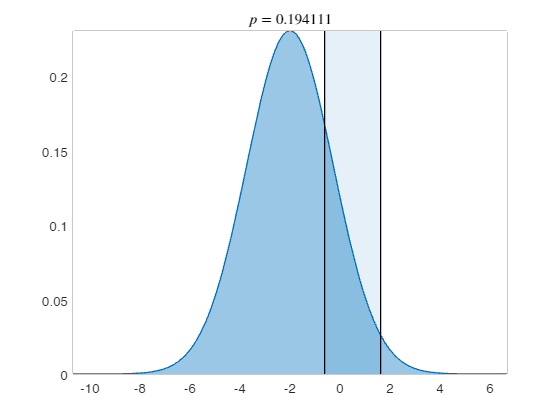

p = 0.1941

figure;
p=integrate_normal(mu,v,quad)

Most plots can be zoomed and panned.

This is the 'normal probability picture', i.e. plot of the normal and its integrated domain. Now plot the 'function probability picture', i.e. the pdf of the scalar function of the normal that defined the domain, and its integrated part.

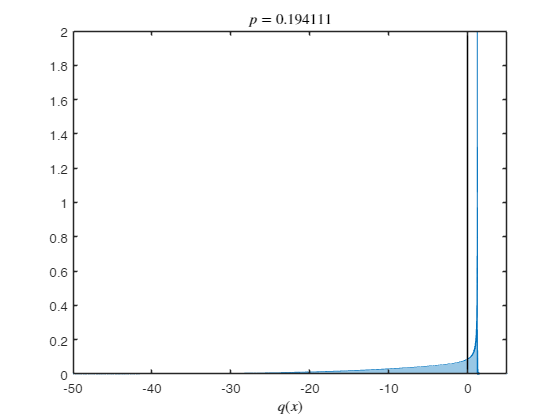

figure;
p=integrate_normal(mu,v,quad,'plotmode','fun_prob');
axis([-50 5 0 2])

### pdf/cdf/inverse cdf of $q(x)$

p=norm_fun_cdf([0 1 2],mu,v,quad)

p =     0.8059    0.9175    1.0000


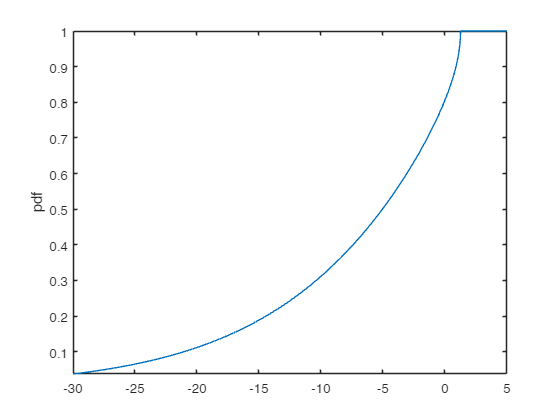

figure;
fplot(@(x) norm_fun_cdf(x,mu,v,quad),[-30 5]); ylabel 'pdf'

f=norm_fun_pdf([0 1 2],mu,v,quad)

f =     0.0865    0.1696         0


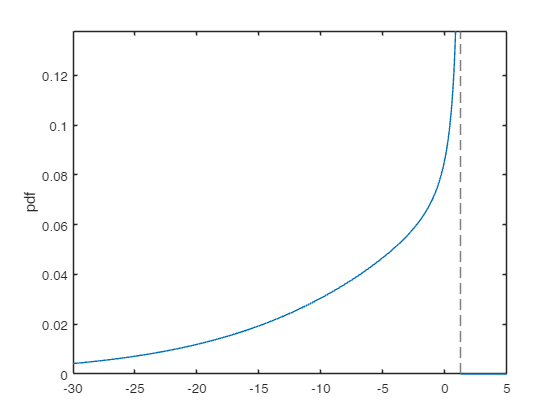

figure;
fplot(@(x) norm_fun_pdf(x,mu,v,quad),[-30 5]); ylabel 'pdf'

1st, 2nd and 3rd quartiles:

x=norm_fun_inv([0.25 0.5 0.75],mu,v,quad)

x =   -12.2134   -5.0417   -0.7030


### normal probability in the domain defined by a non-quadratic function $f(x) =\cos x^2>0$

Also get the boundary points:

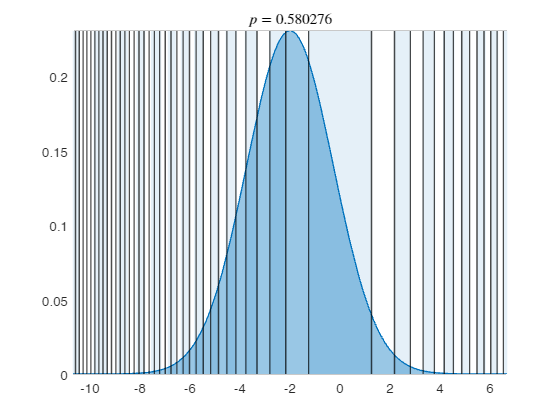

p = 0.5803

bd_pts =   -10.5606  -10.4108  -10.2588  -10.1045   -9.9479   -9.7887   -9.6269   -9.4623   -9.2948   -9.1243   -8.9505   -8.7732   -8.5923   -8.4075   -8.2185   -8.0251   -7.8269   -7.6236   -7.4147   -7.1997   -6.9782   -6.7493   -6.5124   -6.2666   -6.0107   -5.7434   -5.4631   -5.1675   -4.8541   -4.5189   -4.1568   -3.7599   -3.3160   -2.8025   -2.1708   -1.2533    1.2533    2.1708    2.8025    3.3160    3.7599    4.1568    4.5189    4.8541    5.1675    5.4631    5.7434    6.0107    6.2666    6.5124


fun=@(x) cos(x.^2);
[p,~,bd_pts]=integrate_normal(mu,v,fun,'dom_type','fun','fun_span',5,'fun_resol',500,'bd_pts',true)

### Get the function probability picture, i.e. integral of the 1d pdf of $f(x)$

figure;
p=integrate_normal(mu,v,fun,'dom_type','fun','fun_span',5,'fun_resol',500,'plotmode','fun_prob')

p = 0.5803

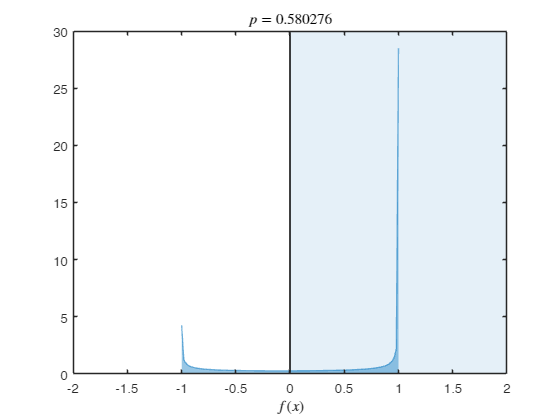

xlim([-2 2])

### Evaluate the cdf of $f(x)$:

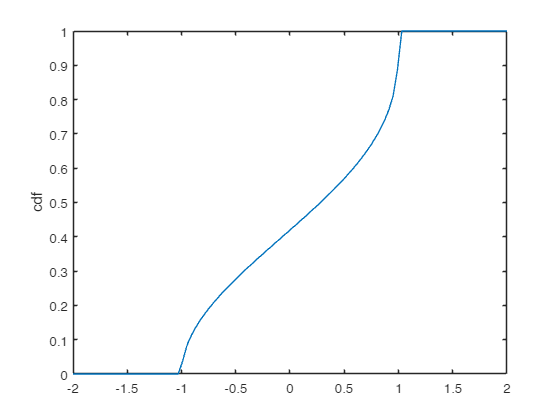

x=linspace(-2,2,100);
F=norm_fun_cdf(x,mu,v,fun,'fun_span',5,'fun_resol',500);
figure;
plot(x,F); ylabel 'cdf'

### Evaluate the pdf of $f(x)$ by numerically differencing the ray-method cdf, or by providing the analytical function derivative to the ray method:

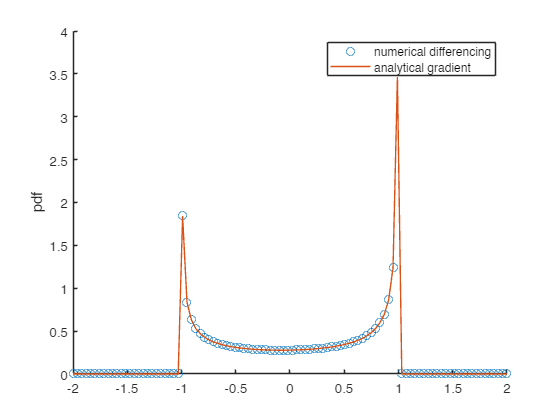

f_diff=norm_fun_pdf(x,mu,v,fun,'fun_span',5,'fun_resol',500);

fun_grad=@(x) -sin(x.^2).*2*x;
f_grad=norm_fun_pdf(x,mu,v,fun,'pdf_method','ray','fun_grad',fun_grad,'fun_span',5,'fun_resol',500);

figure; hold on
plot(x,f_diff,'o');
plot(x,f_grad);
ylabel 'pdf'
legend('numerical differencing','analytical gradient')

### Inverse cdf of $f(x)$

p=[0.5 0.75]; % median and 3rd quartile
x=norm_fun_inv(p,mu,v,fun)

x =     0.2803    0.8832


## Integrate the log-normal distribution

$y \sim \text{lognormal}(\mu=1,\sigma=0.5).$ $p(\sin y > 0)=p(\sin e^x>0)$, where $x \sim N(\mu,\sigma)$.

mu=1; v=.25;

fun=@(x) sin(exp(x));
figure
integrate_normal(mu,v,fun,'dom_type','fun','fun_span',10,'fun_resol',500)

ans = 0.6552

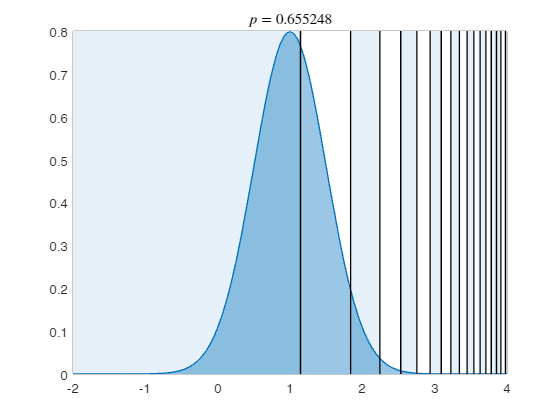

xlim([-2 4])

pdf and cdf of $\sin y$:

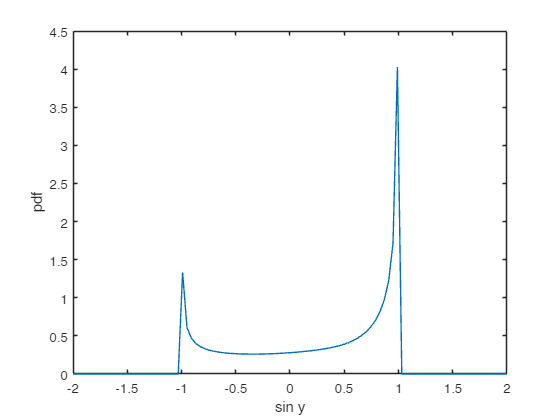

x=linspace(-2,2,100);

f=norm_fun_pdf(x,mu,v,fun,'fun_span',10,'fun_resol',500);
plot(x,f); xlabel 'sin y'; ylabel 'pdf'

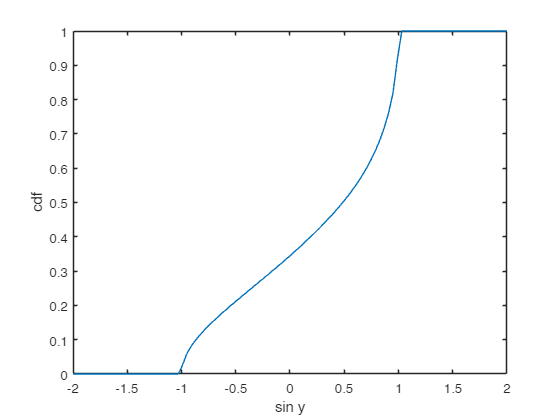

F=norm_fun_cdf(x,mu,v,fun,'fun_span',10,'fun_resol',500);
plot(x,F); xlabel 'sin y'; ylabel 'cdf'

## Classify in 1d

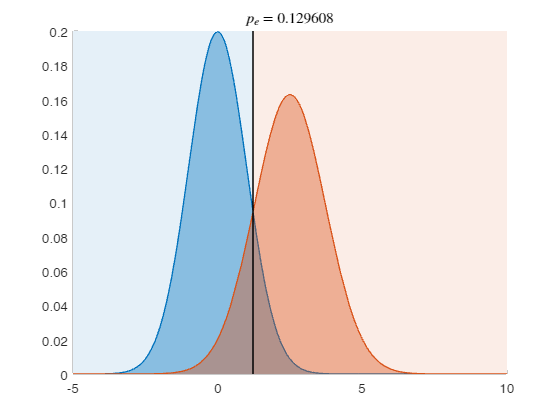

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.1296
       norm_d_b: 2.2565
       norm_d_a: 2.2361
       norm_d_e: 2.2474


mu_1=0; v_1=1;
mu_2=2.5; v_2=1.5;

results=classify_normals([mu_1,v_1],[mu_2,v_2])

Function probability picture:

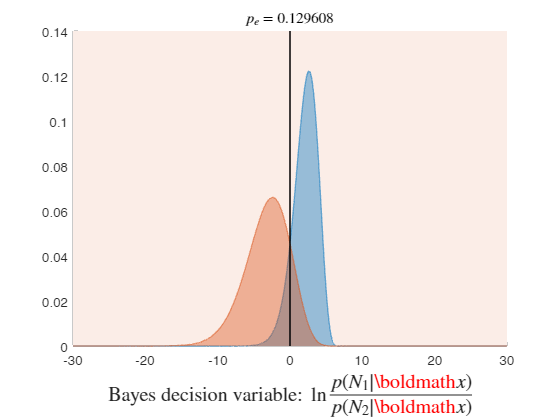

results=classify_normals([mu_1,v_1],[mu_2,v_2],'plotmode','fun_prob');
xlim([-30 30])

### with unequal priors and outcome values

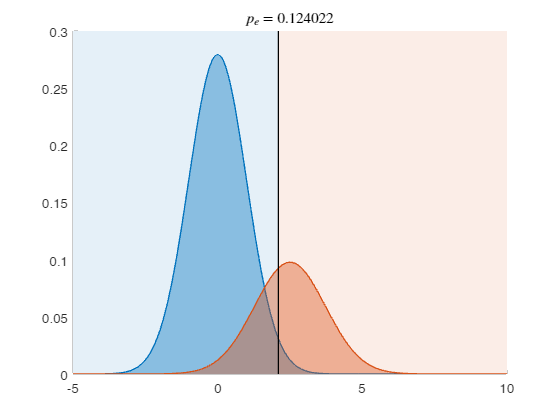

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.1240
       norm_d_b: 2.2565
       norm_d_a: 2.2361
       norm_d_e: 2.2474
    norm_valmat: [2×2 double]
       norm_val: 2.2509


results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[3 0; 0 1])

Function probability picture:

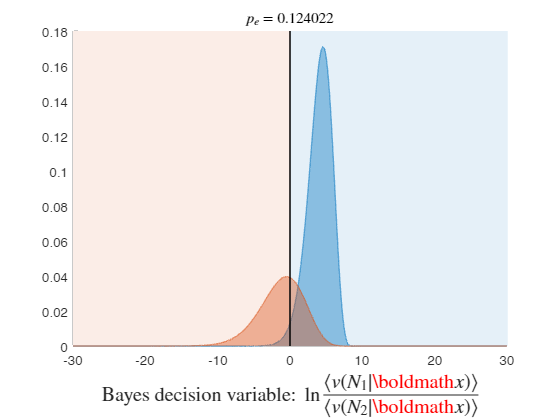

results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[3 0; 0 1],'plotmode','fun_prob');
xlim([-30 30])

## Classify in 1d using samples

Priors are assumed prop. to sample sizes.

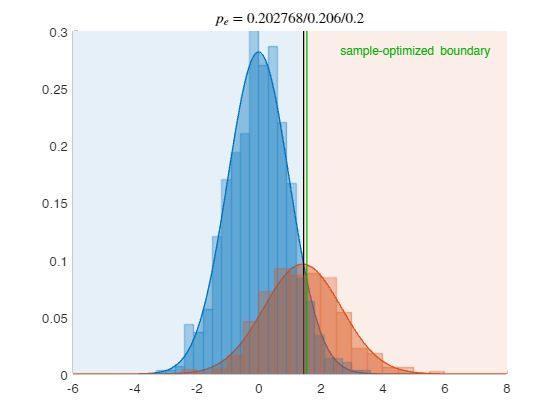

results = struct with fields:
               norm_bd: [1×1 struct]
           norm_errmat: [2×2 double]
              norm_err: 0.2028
              norm_d_b: 1.2930
              norm_d_a: 1.2650
              norm_d_e: 1.2732
               samp_dv: {[700×1 double]  [300×1 double]}
          samp_correct: {[700×1 logical]  [300×1 logical]}
           samp_errmat: [2×2 double]
              samp_err: 0.2060
           samp_ov_err: 0.2643
           samp_opt_bd: [1×1 struct]
           samp_opt_dv: {[700×1 double]  [300×1 double]}
       samp_opt_bd_pts: [-6.4294 1.5450]
    samp_1_opt_correct: [700×1 logical]
    samp_2_opt_correct: [300×1 logical]
       samp_opt_errmat: [2×2 double]
          samp_opt_err: 0.2000


mu_1=0; v_1=1;
samp_1=normrnd(mu_1,sqrt(v_1),[700 1]);

mu_2=1.5; v_2=1.5;
samp_2=normrnd(mu_2,sqrt(v_2),[300 1]);

results=classify_normals(samp_1,samp_2,'input_type','samp')

## Compute $d'_b$ from histogram overlap area

Take two empirical histograms where we don't know the optimal boundary.

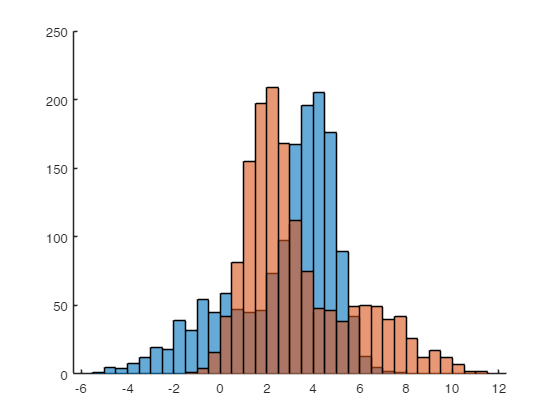

samp_1=[normrnd(0,2,5e2,1); normrnd(4,1,1e3,1)];
samp_2=[normrnd(2,1,1e3,1); normrnd(6,2,5e2,1)];
figure; hold on
histogram(samp_1); histogram(samp_2)

Modeling these with normals will produce a poor estimate of Bayes error rate and Bayes discriminability $d'_b$, even when we optimize the boundary for the sample, since there will be at most two boundaries from a normal model, but here there should be three since the histograms cross three times.

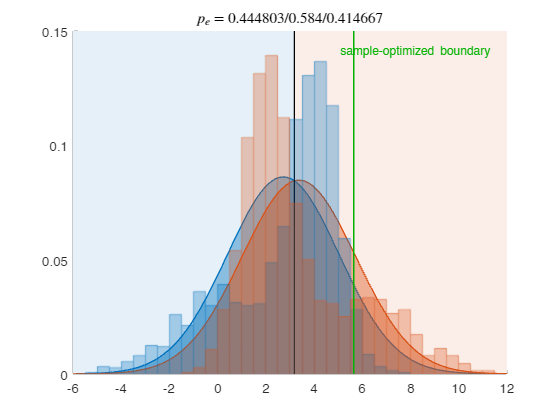

results=classify_normals(samp_1,samp_2,'input_type','samp');
axis([-6 12 0 .15])

results.samp_opt_err

ans = 0.4147

results.samp_opt_d_b

ans = 0.4311

Instead, we can compute the sample histogram overlap area and $d'_b$ from it:

results.samp_ov_err

ans = 0.2510

results.samp_ov_d_b

ans = 1.3427

You can also do this in 2D:

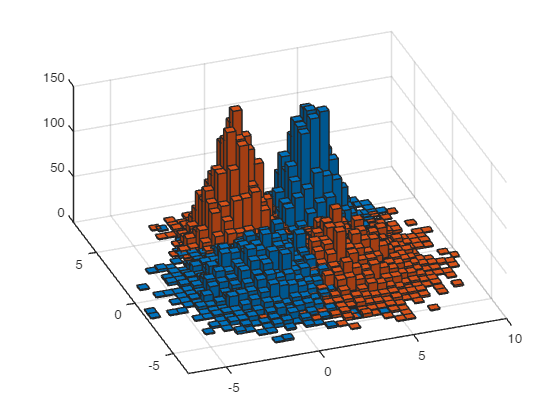

samp_1=[mvnrnd([0 0],3*eye(2),4e3); mvnrnd([4 4],eye(2),4e3)];
samp_2=[mvnrnd([4 0],3*eye(2),4e3); mvnrnd([0 4],eye(2),4e3)];

figure; hold on
histogram2(samp_1(:,1),samp_1(:,2),[30 30],'FaceColor',"#0072BD");
histogram2(samp_2(:,1),samp_2(:,2),[30 30],'FaceColor',"#D95319");
grid on; view([-20 50]); axis([-7 10 -7 8])

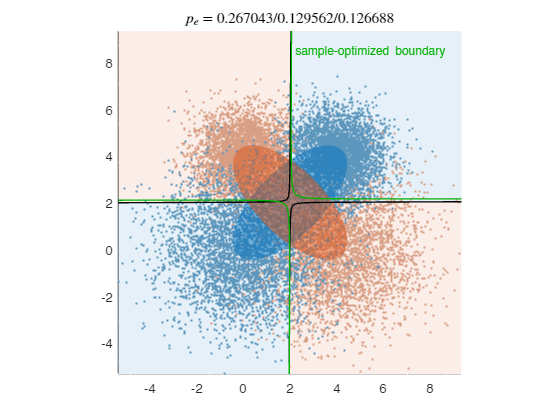

results=classify_normals(samp_1,samp_2,'input_type','samp');

results.samp_ov_err

ans = 0.1260

results.samp_ov_d_b

ans = 2.2910

## Integrate multinormal in 2d (bivariate)

### in a quadratic domain 

defined by $(x+y)^2 > x+1$, i.e.

`q(x,y)= [x y]*[1 1; 1 1]*[x;y] + [-1 0]*[x;y] -1 > 0`

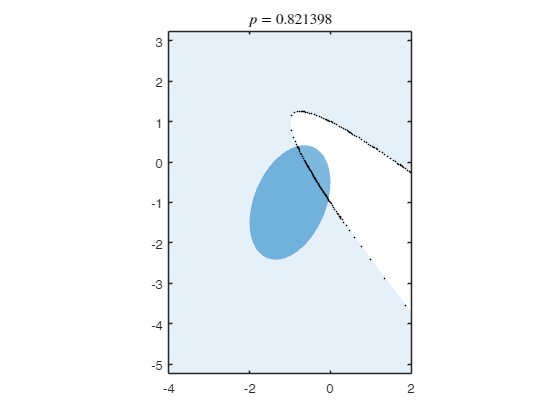

p = 0.8214

bd_pts = 1.0e+03 *

   -0.0001    0.0021   -0.0001    0.0021   -0.0001    0.0021   -0.0001    0.0021   -0.0001    0.0021   -0.0001    0.0021   -0.0001    0.0020   -0.0001    0.0020   -0.0001    0.0019   -0.0002    0.0019   -0.0002    0.0019   -0.0002    0.0018   -0.0002    0.0018   -0.0002    0.0018   -0.0002    0.0017   -0.0002    0.0017   -0.0002    0.0017   -0.0002    0.0017   -0.0002    0.0017   -0.0002    0.0016   -0.0002    0.0015   -0.0002    0.0015   -0.0002    0.0014   -0.0002    0.0013   -0.0003    0.0013
   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0002   -0.0008   -0.0002   -0.0008   -0.0002   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0000   -0.0007    0.0000   -0.0007    0.0000   -0.0007    0.0001   -0.0006    0.0001   -0.0006    0.000

mu=[-1; -1]; v=[1 0.5; 0.5 2];

quad.q2=[1 1; 1 1];
quad.q1=[-1;0];
quad.q0=-1;

% compare two integration algorithms
[p,~,bd_pts]=integrate_normal(mu,v,quad,'method','ray','bd_pts',true) % ray method that plots and gives you computed boundary points

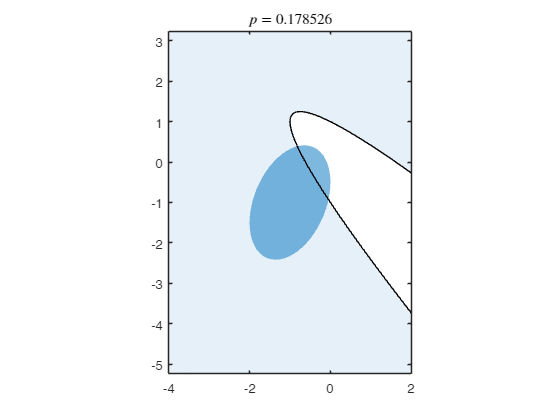

p = 0.1785

p=integrate_normal(mu,v,quad,'method','gx2') % gx2 method

### [[paper fig. 2c]](https://arxiv.org/abs/2012.14331) In a non-quadratic domain

defined by $f(x,y) = x \sin y - y \cos x -1 > 0$:

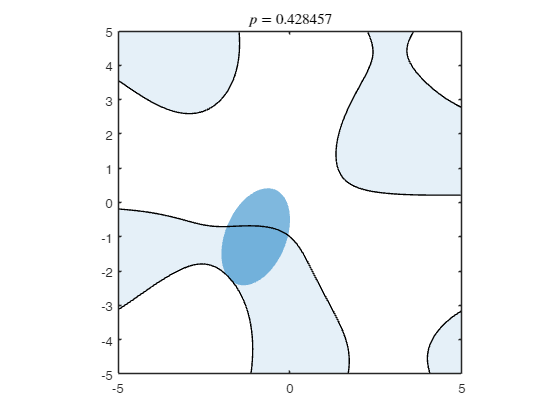

fun=@(x,y) x.*sin(y) - y.*cos(x) -1;
figure
integrate_normal(mu,v,fun,'dom_type','fun','fun_span',3);
axis([-5 5 -5 5])

#### Function probability picture

pdf of $f(x,y)$ and its integrated part:

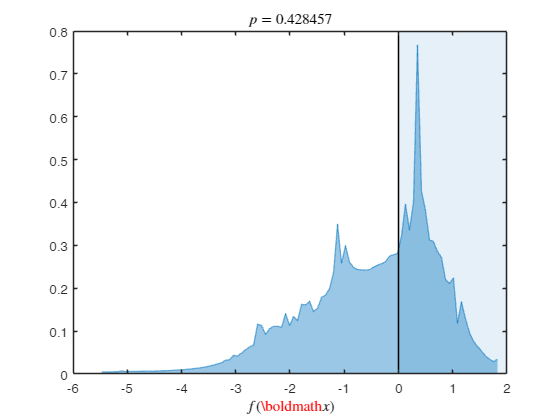

figure
integrate_normal(mu,v,fun,'dom_type','fun','fun_span',3,'plotmode','fun_prob');

## Integrate over rectangular domains (compare to Matlab's `mvncdf`)

*Thanks to *[*Shizhuang Wang*](https://scholar.google.com/citations?user=Xtzve_EAAAAJ)*, Shanghai Jiao Tong University, for collaboration on ideas and code.*

### in 3d

Integrate a 3d normal in the rectangular domain from `[.5; -1; -2]` to `[2; 1; 3]`:

% normal and domain parameters:
mu=[0;0;0];
v=[ 1    0   .1;
    0    2    1;
   .1    1    4];

L=[.5 -1 -2]; U=[2 1 3];

First use Matlab's `mvncdf`:

p=mvncdf(L,U,mu',v)

p = 0.1197

Now using our methods. First use the `rect` domain type:

p=integrate_normal(mu,v,[L;U],'dom_type','rect','bd_pts',true)

p = 0.1196

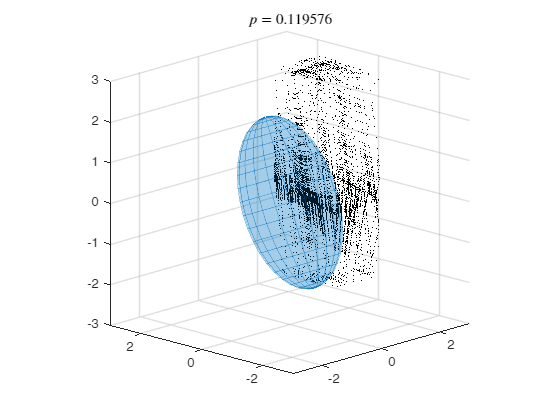

axis image; axis([-3 3 -3 3 -3 3]); view([-46 16]);

We can also instead define the rectangle using the function (`fun`) domain type, just as illustration. This is not the most efficient because the roots of these function domains need to be found numerically:

% domains along each dimension defined as quadratic functions:
fun_x=@(x,y,z) (x-L(1)).*(U(1)-x);
fun_y=@(x,y,z) (y-L(2)).*(U(2)-y);
fun_z=@(x,y,z) (z-L(3)).*(U(3)-z);

% full domain defined by intersection using 'min'
% (arrayfun is used here to properly vectorize fun_full)
fun_full=@(x_array,y_array,z_array) arrayfun(@(x,y,z) min([fun_x(x,y,z) fun_y(x,y,z) fun_z(x,y,z)]), x_array,y_array,z_array);

p=integrate_normal(mu,v,fun_full,'dom_type','fun','AbsTol',0,'RelTol',1e-3,'plotmode',0)

p = 0.1196

A more efficient way is to use quadratic coefficients to define the domain along each dimension, then ray-trace them, then combine (intersect) them using the `and` operator instead of using `min`. This is still not as good as using the `rect` domain type:

The x-domain, say, is defined by $(x-L_1)(U_1-x)>0$, i.e. $-x^2+(L_1+U_1)x-L_1U_1>0.$ That is,

`q(x,y,z)= [x y z]*[-1 0 0; 0 0 0; 0 0 0]*[x;y] + [L(1)+U(1) 0 0]*[x;y;z] -L(1)*U(1) > 0:`

quad_x.q2=[-1 0 0; 0 0 0; 0 0 0];
quad_x.q1=[L(1)+U(1);0;0];
quad_x.q0=-L(1)*U(1);

raytrace_x = @(n,orig) standard_ray_trace(quad_x,n,'mu',orig);

quad_y.q2=[0 0 0; 0 -1 0; 0 0 0];
quad_y.q1=[0;L(2)+U(2);0];
quad_y.q0=-L(2)*U(2);

raytrace_y = @(n,orig) standard_ray_trace(quad_y,n,'mu',orig);

quad_z.q2=[0 0 0; 0 0 0; 0 0 -1];
quad_z.q1=[0;0;L(3)+U(3)];
quad_z.q0=-L(3)*U(3);

raytrace_z = @(n,orig) standard_ray_trace(quad_z,n,'mu',orig);

raytrace_full = @(n,orig) combine_ray_trace_doms({raytrace_x;raytrace_y;raytrace_z},'and',n,'orig',orig);

p=integrate_normal(mu,v,raytrace_full,'dom_type','ray_trace','plotmode',0)

p = 0.1196

### in 4d

% parameters:
mu=[0;0;0;0];
v=[ 1    0    0   .1;
    0   .8    0   .2;
    0    0   .7   .3
   .1   .2   .3    1];

L=[-1 -3 -7 -5]; U=[3 1 2 1];

% matlab's mvncdf
p=mvncdf(L,U,mu',v)

p = 0.6166


% our method
p=integrate_normal(mu,v,[L;U],'dom_type','rect','plotmode',0)

p = 0.6170

## [[paper 1, sec. 2.2.6]](https://arxiv.org/abs/2012.14331) probabilities of a function $x^y$ of a 2d (bivariate) multinormal

mu=[1;2]; v=.01*[1 1.6; 1.6 4];
fun=@(x,y) x.^y;

### cdf

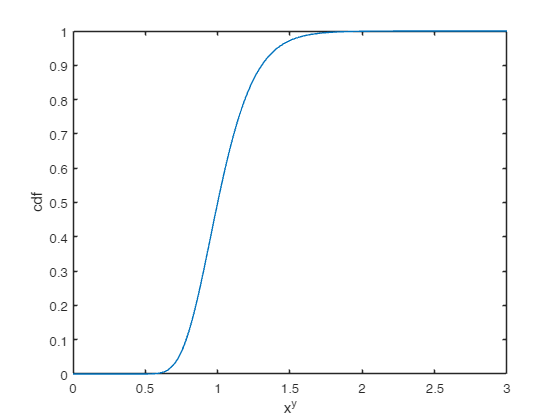

dx=.01; x=0:dx:3;
F=norm_fun_cdf(x,mu,v,fun,'fun_span',5,'fun_resol',500);
plot(x,F); xlabel x^y; ylabel 'cdf'

### pdf

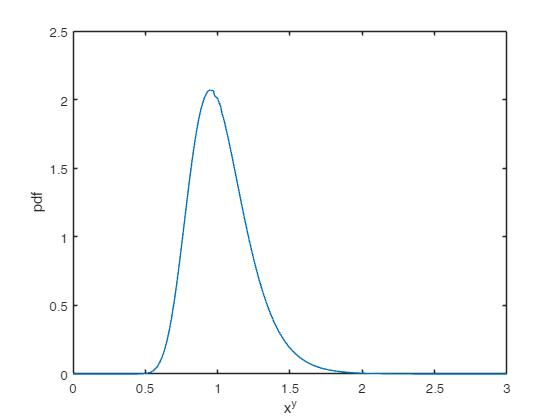

f=norm_fun_pdf(x,mu,v,fun,'fun_span',5,'fun_resol',500,'dx',1e-2);
plot(x,f); xlabel x^y; ylabel 'pdf'

Verify that pdf sums to 1:

sum(f)*dx

ans = 1.0000

### Mean of $x^y$

m=sum(x.*f)*dx

m = 1.0266

### sd of $x^y$

m2=sum(x.^2.*f)*dx;
sd=sqrt(m2-m^2)

sd = 0.2115

### median of $x^y$

norm_fun_inv(.5,mu,v,fun)

ans = 1.0000

## Joint probability of functions of a normal

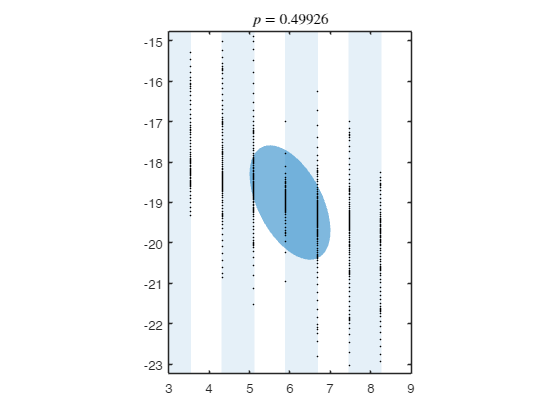

% (x,y) is a normal vector with these parameters:
mu=[6;-19];
v=[1 -.7; -.7 2];

% functions of the normal vector
fun1=@(x,y) cos(4*x);
fun2=@(x,y) cos(4*y);

% p(cos 4x > 0), show the boundary points computed by the ray method
integrate_normal(mu,v,fun1,'dom_type','fun','fun_span',3,'bd_pts',true); axis image

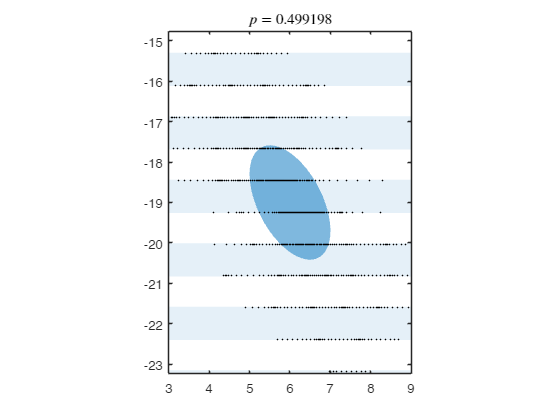

% p(cos 4y > 0)
integrate_normal(mu,v,fun2,'dom_type','fun','fun_span',3,'bd_pts',true); axis image

Probability that $cos(4x)$ and $cos(4y)$ are both > 0, i.e. integrate the normal in the domain $\min (\cos 4x, \cos 4y)>0$:

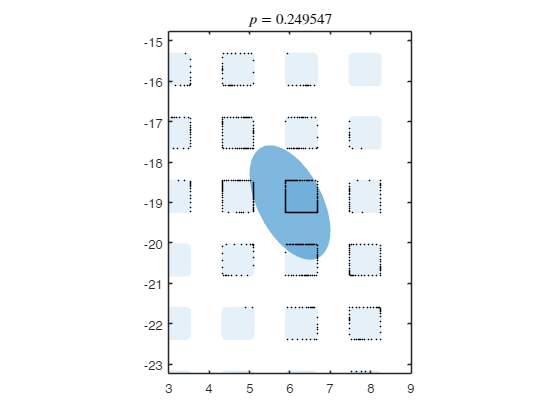

fun3=@(x,y) min(fun1(x,y),fun2(x,y));
p=integrate_normal(mu,v,fun3,'dom_type','fun','fun_span',3,'bd_pts',true); axis image

Probability that $cos(4x) + cos(4y) > 0.5$, i.e. integrate the normal in the domain $cos(4x) + cos(4y) + 0.5 > 0$

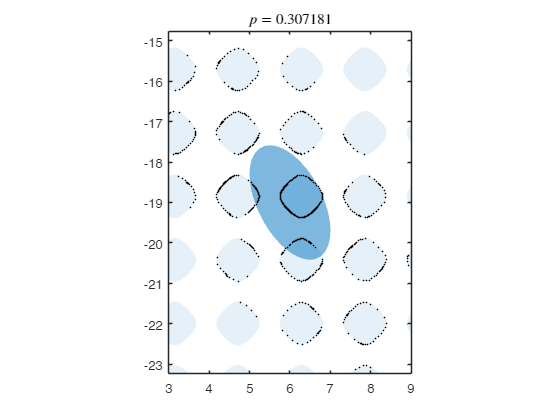

fun4=@(x,y) fun1(x,y)+fun2(x,y)-0.5;
p=integrate_normal(mu,v,fun4,'dom_type','fun','fun_span',3,'bd_pts',true); axis image

Percentage points (inverse cdf):

p=[0.5 0.75];
x=norm_fun_inv(p,mu,v,fun4)

x =    -0.4999    0.2210


## Classify two 2d (bivariate) multinormals with the same mean

mu_1=[4; 5]; v_1=[2 1; 1 1];
mu_2=mu_1; v_2=3*[2 -1; -1 1];

Ray method:

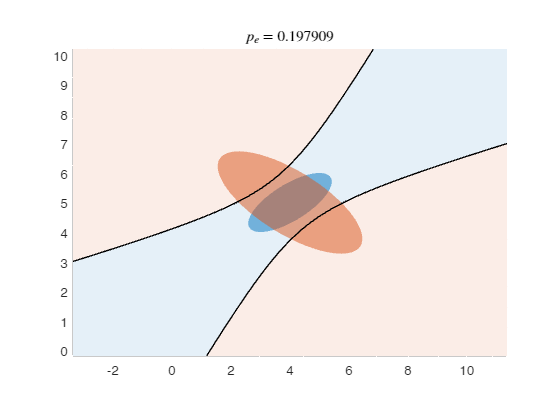

results_ray = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.1979
       norm_d_b: 1.6982
       norm_d_a: 0
       norm_d_e: 0


results_ray=classify_normals([mu_1,v_1],[mu_2,v_2])

This is the normal probability picture. Now see the function probability picture:

results_ray=classify_normals([mu_1,v_1],[mu_2,v_2],'plotmode','fun_prob')

results_ray = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.1979
       norm_d_b: 1.6982
       norm_d_a: 0
       norm_d_e: 0


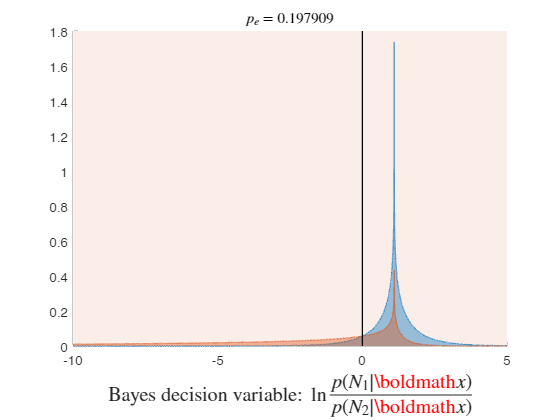

xlim([-10 5])

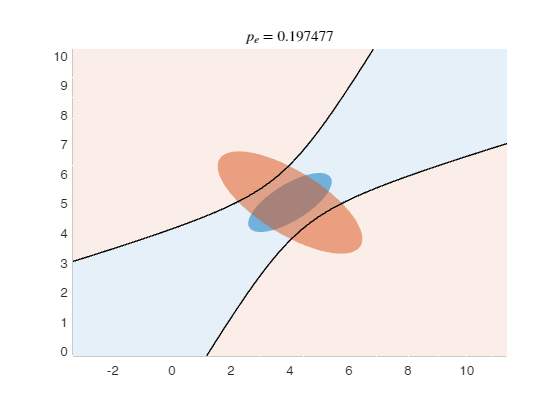

results_gx2 = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.1975
       norm_d_b: 1.7013
       norm_d_a: 0
       norm_d_e: 0


results_gx2=classify_normals([mu_1,v_1],[mu_2,v_2],'method','gx2') % gx2 method

## [[paper 1, fig. 2d]](https://arxiv.org/abs/2012.14331) Classify in 2d with custom boundaries and from samples, and compute decision variable

mu_1=[2;4]; v_1=[1 1.5; 1.5 3];
mu_2=[5;0]; v_2=[3 0; 0 1];

Use the ray method to find the overall $d'$, and also compute the fractional contribution of each dimension to the total $d'$:

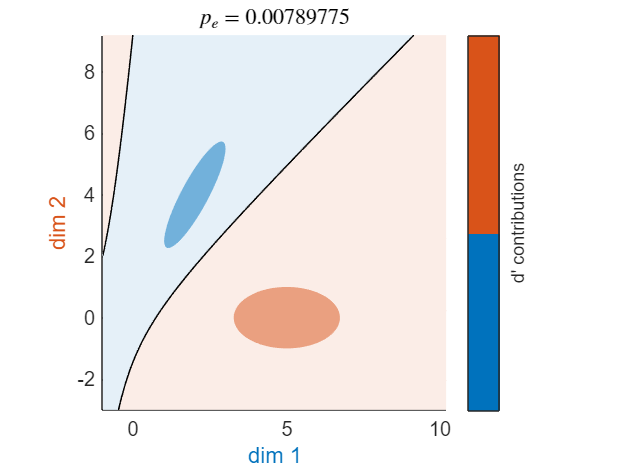

results_ray = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.0079
       norm_d_b: 4.8272
       norm_d_a: 4.4477
       norm_d_e: 5.1149
          d_con: [2×1 double]


results_ray=classify_normals([mu_1,v_1],[mu_2,v_2],'d_con',true)

format long; results_ray.norm_err

ans =    0.007897753149045


Compare with generalized chi square method:

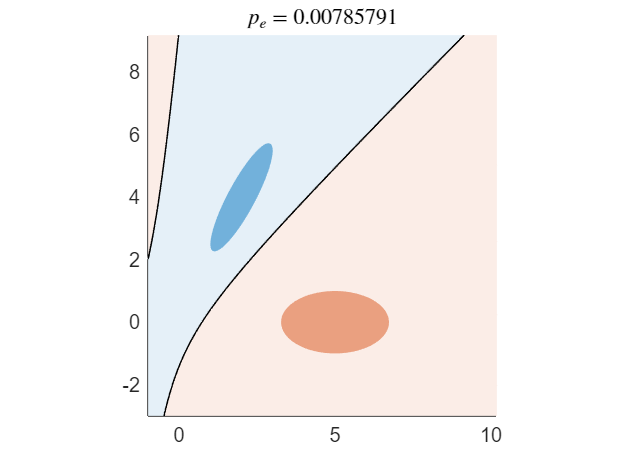

results_gx2=classify_normals([mu_1,v_1],[mu_2,v_2],'method','gx2');

format long; results_gx2.norm_err

ans =    0.007857913740419


Now pass the optimal domain in function format:

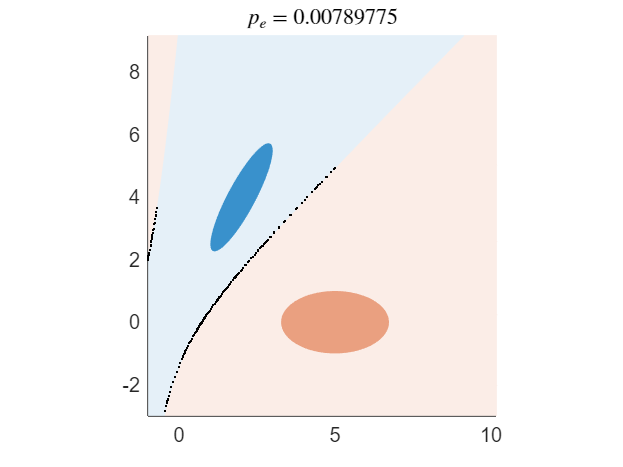

results_fun = struct with fields:
    norm_bd_pts: [2×326 double]
    norm_errmat: [2×2 double]
       norm_err: 0.007897751962520
       norm_d_b: 4.827213214038089
       norm_d_a: 4.447675593140555
       norm_d_e: 5.114936224685255


dom=results_gx2.norm_bd;

a_x2=dom.q2(1,1);
a_y2=dom.q2(2,2);
a_xy=dom.q2(1,2)+dom.q2(2,1);
a_x=dom.q1(1);
a_y=dom.q1(2);
a_0=dom.q0;

dom_fun=@(x,y) a_x2*(x.^2)+a_y2*(y.^2)+a_xy*(x.*y)+a_x*x+a_y*y+a_0;
results_fun=classify_normals([mu_1,v_1],[mu_2,v_2],'dom',dom_fun,'dom_type','fun','bd_pts',true)

results_fun.norm_err

ans =    0.007897751962520


format

Now supply a custom linear boundary in quadratic coefficients format:

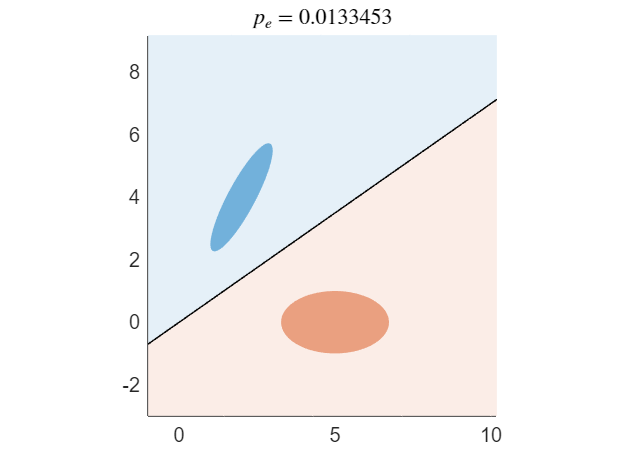

results_linear = struct with fields:
    norm_errmat: [2×2 double]
       norm_err: 0.0133
       norm_d_b: 4.8272
       norm_d_a: 4.4477
       norm_d_e: 5.1149


linear_bd.q2=zeros(2);
linear_bd.q1=[-.7;1];
linear_bd.q0=0;

results_linear=classify_normals([mu_1,v_1],[mu_2,v_2],'dom',linear_bd)

Now supply the linear boundary in function format:

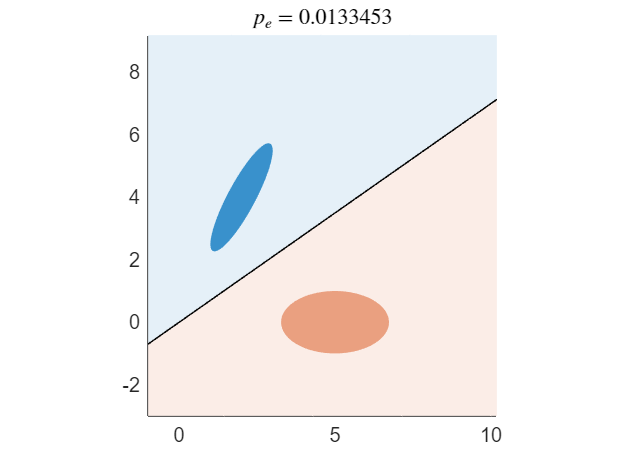

results_linear_fun = struct with fields:
    norm_errmat: [2×2 double]
       norm_err: 0.0133
       norm_d_b: 4.8272
       norm_d_a: 4.4477
       norm_d_e: 5.1149


linear_bd_fun=@(x,y) y-0.7*x;
results_linear_fun=classify_normals([mu_1,v_1],[mu_2,v_2],'dom',linear_bd_fun,'dom_type','fun')

Now classify using samples:

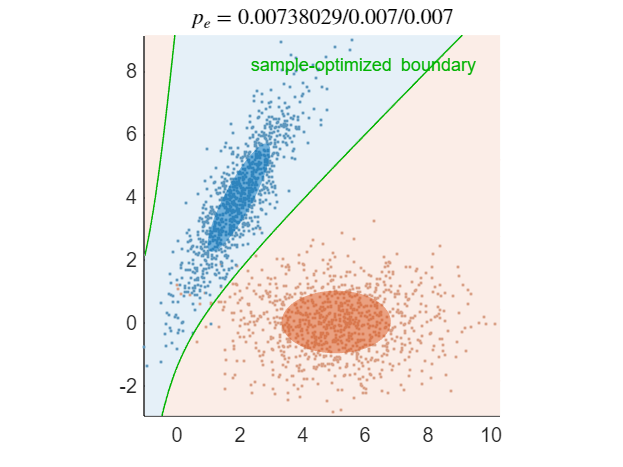

results_samp = struct with fields:
               norm_bd: [1×1 struct]
           norm_errmat: [2×2 double]
              norm_err: 0.0074
              norm_d_b: 4.8764
              norm_d_a: 4.4837
              norm_d_e: 5.1618
               samp_dv: {[1000×1 double]  [1000×1 double]}
          samp_correct: {[1000×1 logical]  [1000×1 logical]}
           samp_errmat: [2×2 double]
              samp_err: 0.0070
           samp_ov_err: 0.0090
              samp_d_b: 4.9145
           samp_ov_d_b: 4.7312
           samp_opt_bd: [1×1 struct]
           samp_opt_dv: {[1000×1 double]  [1000×1 double]}
       samp_opt_bd_pts: [2×31964 double]
    samp_1_opt_correct: [1000×1 logical]
    samp_2_opt_correct: [1000×1 logical]
       samp_opt_errmat: [2×2 double]
          samp_opt_err: 0.0070
          samp_opt_d_b: 4.9145


n_samp=1e3;
samp_1=mvnrnd(mu_1,v_1,n_samp);
samp_2=mvnrnd(mu_2,v_2,n_samp);

results_samp=classify_normals(samp_1,samp_2,'input_type','samp')

Now compute decision variables (log-likelihood ratio) based on this decision boundary:

% quadratic coefficients of the sample-optimal decision boundary
quad=results_samp.samp_opt_bd;
% (you could also use the normal-optimal decision boundary results.samp_bd

% create a decision-variable function from these coefficients
dvfun=quad2fun(quad,0,0);

% now take any point as a column vector
x=[8 8]'; 

% compute decision variable of the point
dvfun(x)

ans = -0.7235

% plot a contour map of the decision variable field over a region
figure;
fcontour(@(x,y) dvfun([x y]'),[-1 10 -3 9],'fill','on','levellist',-200:20:50)

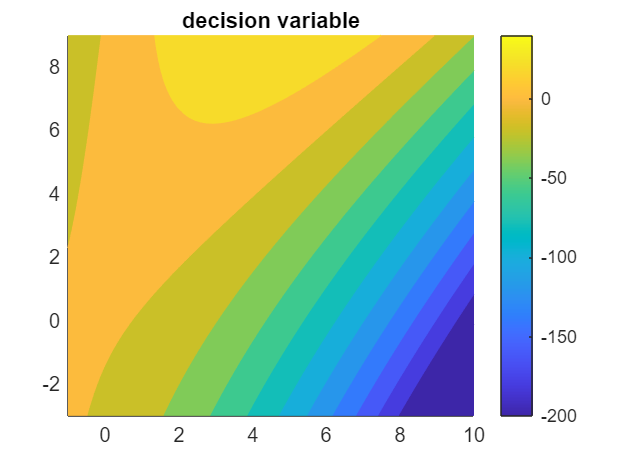

colorbar
title('decision variable')

Function probability picture of the classification of the samples:

results_samp=classify_normals(samp_1,samp_2,'input_type','samp','plotmode','fun_prob')

results_samp = struct with fields:
               norm_bd: [1×1 struct]
           norm_errmat: [2×2 double]
              norm_err: 0.0074
              norm_d_b: 4.8764
              norm_d_a: 4.4837
              norm_d_e: 5.1618
               samp_dv: {[1000×1 double]  [1000×1 double]}
          samp_correct: {[1000×1 logical]  [1000×1 logical]}
           samp_errmat: [2×2 double]
              samp_err: 0.0070
           samp_ov_err: 0.0090
              samp_d_b: 4.9145
           samp_ov_d_b: 4.7312
           samp_opt_bd: [1×1 struct]
           samp_opt_dv: {[1000×1 double]  [1000×1 double]}
       samp_opt_bd_pts: [2×31964 double]
    samp_1_opt_correct: [1000×1 logical]
    samp_2_opt_correct: [1000×1 logical]
       samp_opt_errmat: [2×2 double]
          samp_opt_err: 0.0070
          samp_opt_d_b: 4.9145


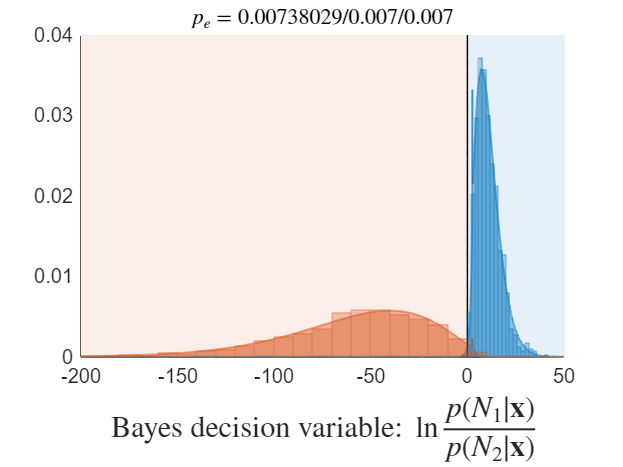

xlim([-200 50])

Modify the sample-optimized boundary and classify with it:

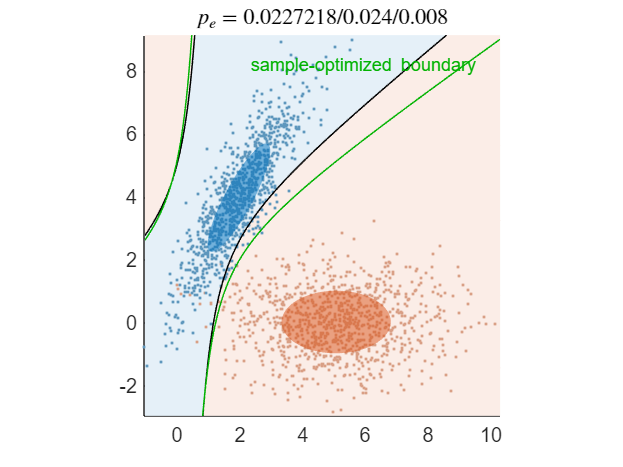

results_samp_custom = struct with fields:
           norm_errmat: [2×2 double]
              norm_err: 0.0227
              norm_d_b: 4.8764
              norm_d_a: 4.4837
              norm_d_e: 5.1618
               samp_dv: {[1000×1 double]  [1000×1 double]}
          samp_correct: {[1000×1 logical]  [1000×1 logical]}
           samp_errmat: [2×2 double]
              samp_err: 0.0240
           samp_ov_err: 0.0090
           samp_opt_bd: [1×1 struct]
           samp_opt_dv: {[1000×1 double]  [1000×1 double]}
       samp_opt_bd_pts: [2×26802 double]
    samp_1_opt_correct: [1000×1 logical]
    samp_2_opt_correct: [1000×1 logical]
       samp_opt_errmat: [2×2 double]
          samp_opt_err: 0.0080


custom_bd=results_samp.samp_opt_bd;
custom_bd.q2=custom_bd.q2+.1;
custom_bd.q1=custom_bd.q1-2.5;
custom_bd.q0=custom_bd.q0+5;

results_samp_custom=classify_normals(samp_1,samp_2,'input_type','samp','dom',custom_bd)

## Use integration/classification domains in three different formats

mu=[1;7];
v=[1 .5; .5 2];

Integrate this 2d normal in the domain defined by the line $y>1$, using three different domain formats.

### Ray-trace format

Construct the domain as a ray-trace function, which specifies the initial sign and crossing points of the domain along any ray.

open line_ray_trace

Plot the domain boundary:

figure
plot_boundary(@line_ray_trace,2,'dom_type','ray_trace')

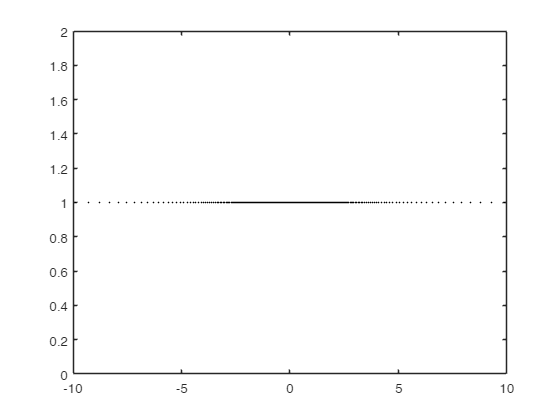

axis([-10 10 0 2])

Integrate in this domain:

format long
figure;
p=integrate_normal(mu,v,@line_ray_trace,'dom_type','ray_trace')

p =    0.999988954751501


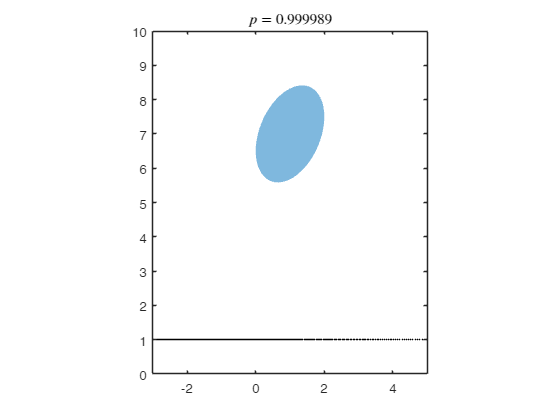

axis([-3 5 0 10])

### Quadratic format

This can only be used if the domain is quadratic.

$y>1$⇒$0.x^2+0.y^2+0.xy+0.x+1.y-1>0$,

i.e. `[x y]*[0 0; 0 0]*[x;y] + [0 1]*[x;y] -1 > 0`

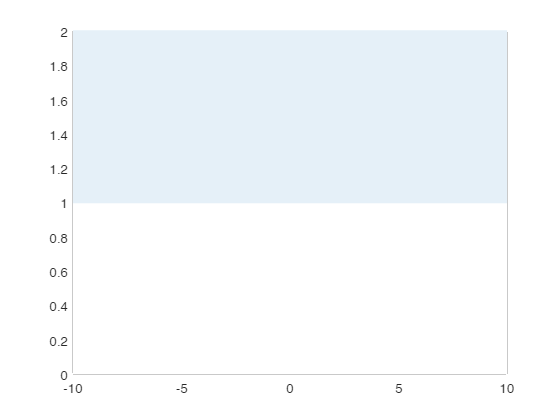

line_quad.q2=zeros(2);
line_quad.q1=[0;1];
line_quad.q0=-1;

plot_boundary(line_quad,2,'dom_type','quad','fill_colors',[0,0.447,0.741])
axis([-10 10 0 2])

[~,pc]=integrate_normal(mu,v,line_quad,'dom_type','quad')


pc =

     []



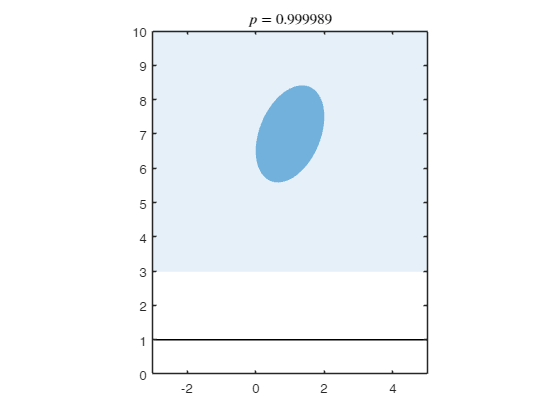

axis([-3 5 0 10])

### Function format

This general function format is simple. But a numerical algorithm is used to find its crossing points in a finite span, so compared to the above two formats, it can be less accurate for the same speed.

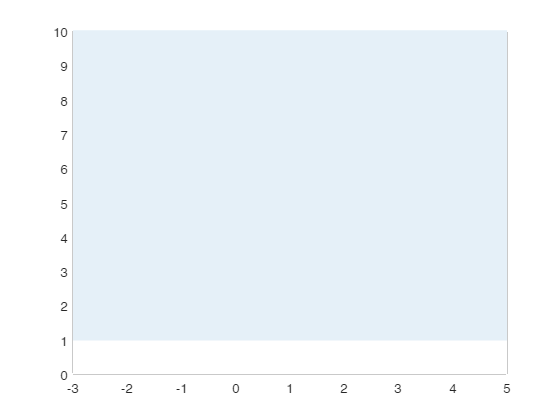

line_fun=@(x,y) y-1;
plot_boundary(line_fun,2,'dom_type','fun','fill_colors',[0,0.447,0.741])

[~,pc]=integrate_normal(mu,v,line_fun,'dom_type','fun')


pc =

     []



axis([-3 5 0 10])

Improve accuracy by changing `AbsTol`, `RelTol`, `fun_span` or `fun_resol`:

[~,pc]=integrate_normal(mu,v,line_fun,'dom_type','fun','fun_span',10)


pc =

     []



axis([-3 5 0 10])

Classify normals and samples using these domain formats.

mu_2=[-1;-2];
v_2=[1 -.5; -.5 2];
n_samp=1e3;
samp_1=mvnrnd(mu,v,n_samp);
samp_2=mvnrnd(mu_2,v_2,n_samp);

### Ray-trace format

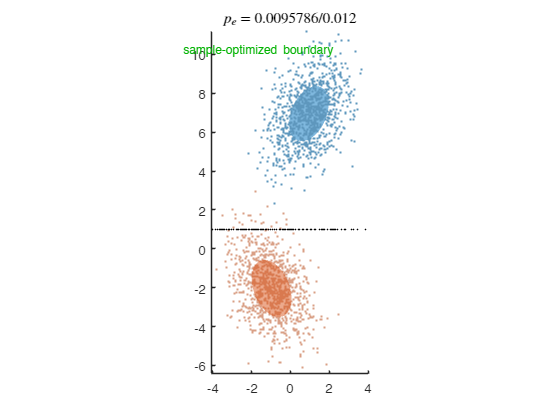

results = struct with fields:
     norm_bd_pts: [2×300 double]
     norm_errmat: [2×2 double]
        norm_err: 0.009578596814356
        norm_d_b: 6.559356164170135
        norm_d_a: 6.522666223653403
        norm_d_e: 6.597984118848756
    samp_correct: {[1×1000 logical]  [1×1000 logical]}
     samp_errmat: [2×2 double]
        samp_err: 0.012000000000000
     samp_ov_err: 5.000000000000000e-04


results=classify_normals(samp_1,samp_2,'input_type','samp','dom',@line_ray_trace,'dom_type','ray_trace')

### Quadratic format

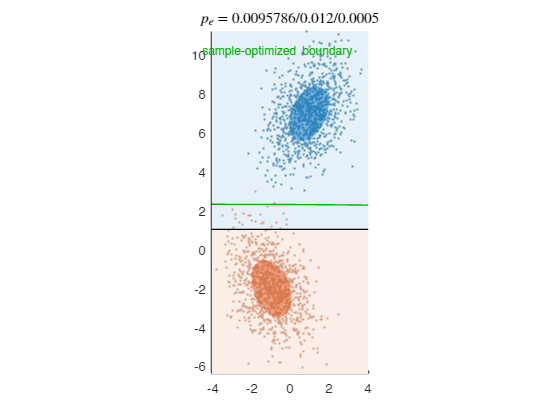

results = struct with fields:
           norm_errmat: [2×2 double]
              norm_err: 0.009578596814356
              norm_d_b: 6.559356164170135
              norm_d_a: 6.522666223653403
              norm_d_e: 6.597984118848756
               samp_dv: {[1000×1 double]  [1000×1 double]}
          samp_correct: {[1000×1 logical]  [1000×1 logical]}
           samp_errmat: [2×2 double]
              samp_err: 0.012000000000000
           samp_ov_err: 5.000000000000000e-04
           samp_opt_bd: [1×1 struct]
           samp_opt_dv: {[1000×1 double]  [1000×1 double]}
       samp_opt_bd_pts: [2×39117 double]
    samp_1_opt_correct: [1000×1 logical]
    samp_2_opt_correct: [1000×1 logical]
       samp_opt_errmat: [2×2 double]
          samp_opt_err: 5.000000000000000e-04


results=classify_normals(samp_1,samp_2,'input_type','samp','dom',line_quad,'dom_type','quad')

### Function format

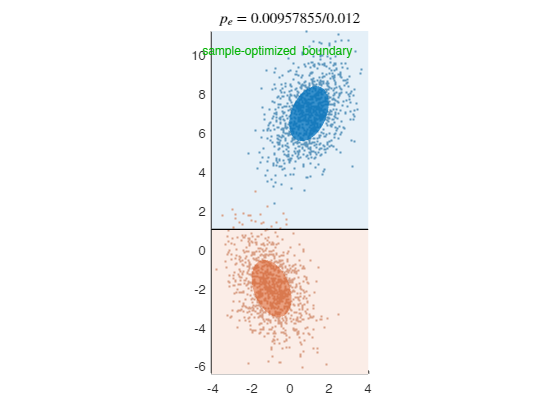

results = struct with fields:
     norm_errmat: [2×2 double]
        norm_err: 0.009578551431331
        norm_d_b: 6.559356164170135
        norm_d_a: 6.522666223653403
        norm_d_e: 6.597984118848756
         samp_dv: {[1000×1 double]  [1000×1 double]}
    samp_correct: {[1000×1 logical]  [1000×1 logical]}
     samp_errmat: [2×2 double]
        samp_err: 0.012000000000000
     samp_ov_err: 5.000000000000000e-04


results=classify_normals(samp_1,samp_2,'input_type','samp','dom',line_fun,'dom_type','fun')

## [[paper 1, fig. 2e]](https://arxiv.org/abs/2012.14331) Classify in 2d with non-normal samples

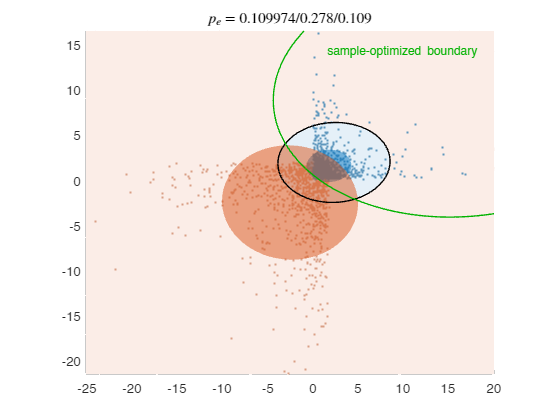

results = struct with fields:
               norm_bd: [1×1 struct]
           norm_errmat: [2×2 double]
              norm_err: 0.109974414431712
              norm_d_b: 2.453328398197451
              norm_d_a: 1.175255970215929
              norm_d_e: 1.327870476637240
               samp_dv: {[1000×1 double]  [1000×1 double]}
          samp_correct: {[1000×1 logical]  [1000×1 logical]}
           samp_errmat: [2×2 double]
              samp_err: 0.278000000000000
           samp_ov_err: 0.074000000000000
              samp_d_b: 1.177586423821839
           samp_ov_d_b: 2.893264134317957
           samp_opt_bd: [1×1 struct]
           samp_opt_dv: {[1000×1 double]  [1000×1 double]}
       samp_opt_bd_pts: [2×31526 double]
    samp_1_opt_correct: [1000×1 logical]
    samp_2_opt_correct: [1000×1 logical]
       samp_opt_errmat: [2×2 double]
          samp_opt_err: 0.109000000000000
          samp_opt_d_b: 2.463727417469966


n_samp=1e3;
samp_1=exp(mvnrnd([0 0],eye(2),n_samp));
samp_2=-exp(mvnrnd([1 1],eye(2),n_samp))+[2 2];

results=classify_normals(samp_1,samp_2,'input_type','samp')

## [[paper 1, fig. 6]](https://arxiv.org/abs/2012.14331) Scale the discriminability of two distributions

### By linearly warping one distribution towards another:

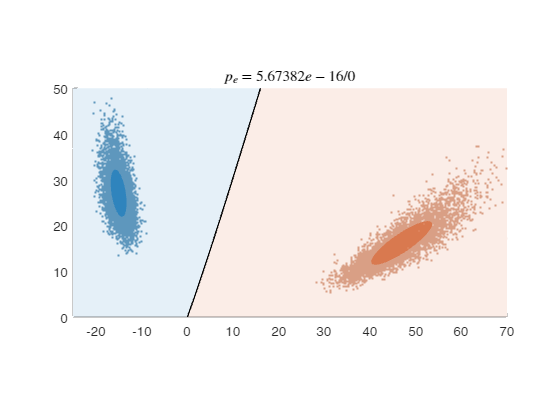

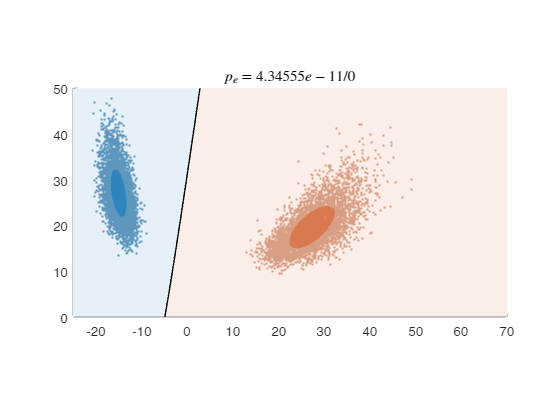

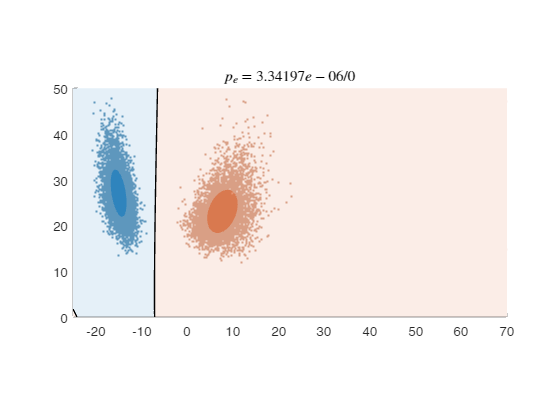

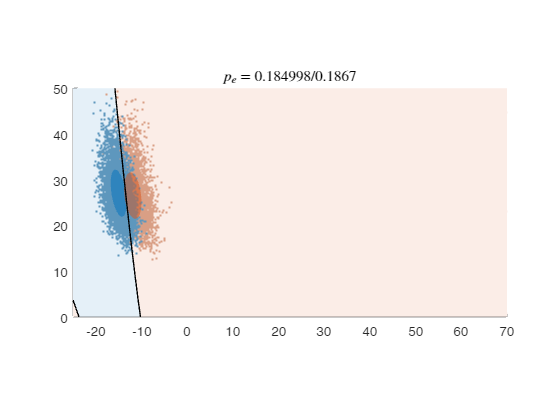

% generate two samples, can be non-normal

mu_1=[-10;5]; v_1=[10 -2; -2 2]*.3;
mu_2=[6;5]; v_2=[1 1.5; 1.5 3]*.02;

n_samp=5e3;
samp_1=mvnrnd(mu_1,v_1,n_samp);
samp_2=mvnrnd(mu_2,v_2,n_samp);

samp_1(:,2)=samp_1(:,2).^2/1.5;
samp_1=samp_1+[-5 10];
samp_2=samp_2.^6/1e3;

% scale the discriminability by using an interpolation factor to warp
% distribution b towards a:

d_scale_list=linspace(1,0.05,4);

for i=1:length(d_scale_list)
    results=classify_normals(samp_1,samp_2,'input_type','samp','d_scale',d_scale_list(i),'samp_opt',false);    
    axis image; axis([-25 70 0 50])
end

### By moving the Bayes decision variables (log likelihood ratios) towards 0:

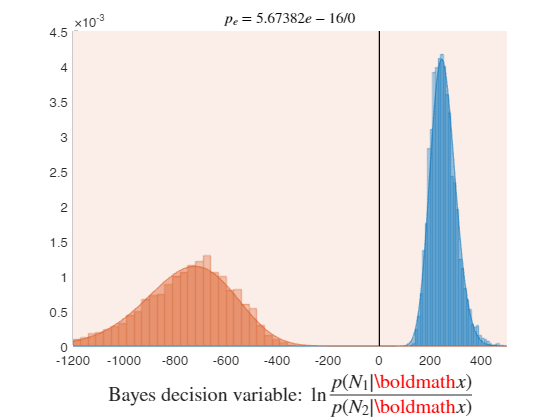

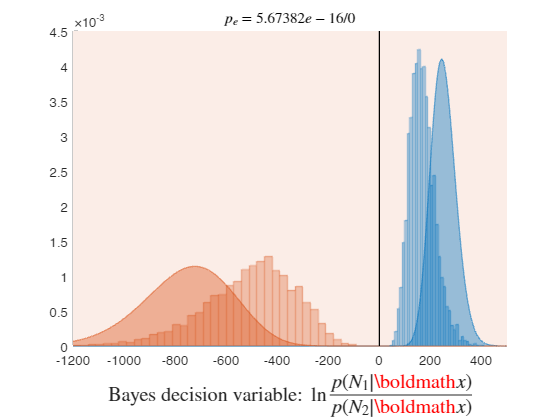

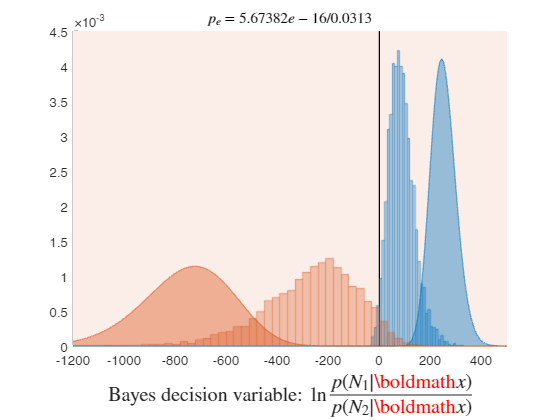

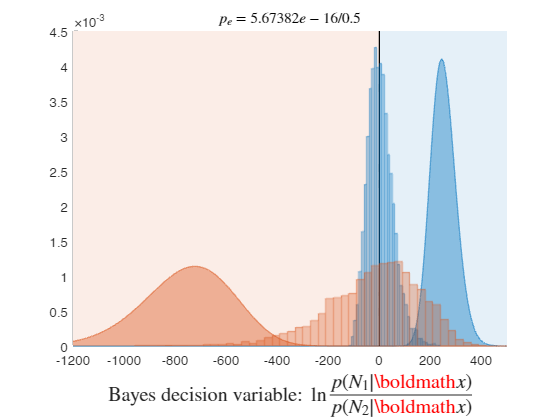

% scale the discriminability by using an interpolation factor to warp
% distribution b towards a:

d_scale_list=linspace(1,0.0,4);
for i=1:length(d_scale_list)
    results=classify_normals(samp_1,samp_2,'input_type','samp','samp_opt',false,'d_scale',d_scale_list(i),'d_scale_type','squeeze_dv','plotmode','fun_prob');    
    xlim([-1200 500])
end

## [[paper 1, fig. 2a, bottom]](https://arxiv.org/abs/2012.14331) Set operations on integration/classification domains

mu=[0;0]; v=[.5 0; 0 1];

left_circle_fun=@(x,y) -(x+1).^2-y.^2+5;
right_circle_fun=@(x,y) -(x-1).^2-y.^2+5;

Union of the two circles is: left circle >0 or right circle equation >0, i.e. max (left circle equation, right circle equation)>0:

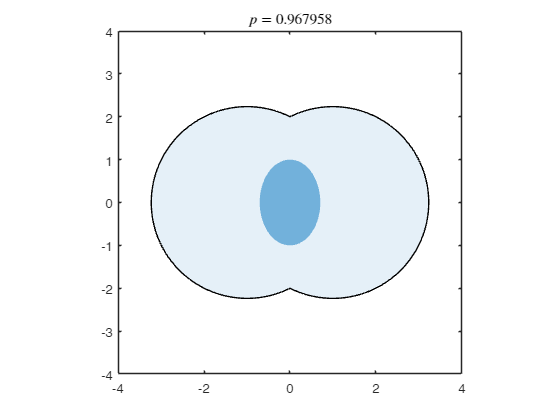

union_fun=@(x,y) max(left_circle_fun(x,y), right_circle_fun(x,y));
integrate_normal(mu,v,union_fun,'dom_type','fun','fun_span',5);
axis image; axis([-4 4 -4 4])

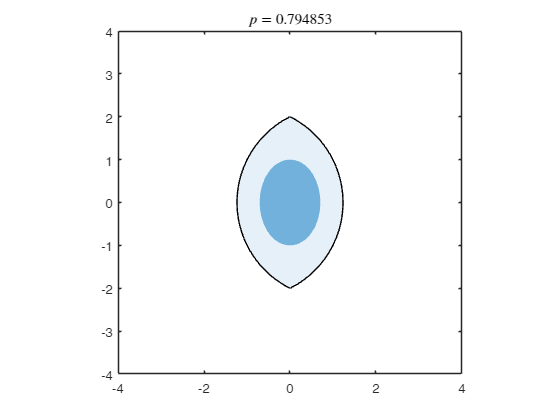

intersection_fun=@(x,y) min(left_circle_fun(x,y), right_circle_fun(x,y));
integrate_normal(mu,v,intersection_fun,'dom_type','fun','fun_span',5);
axis image; axis([-4 4 -4 4])

Create a crescent domain: (left circle) OR  (NOT (right circle)), i.e. left circle equation > 0 or right circle equation < 0, i.e. left circle equation > 0 or minus of right circle equation > 0, i.e. max(left circle equation, minus of right circle equation)>0:

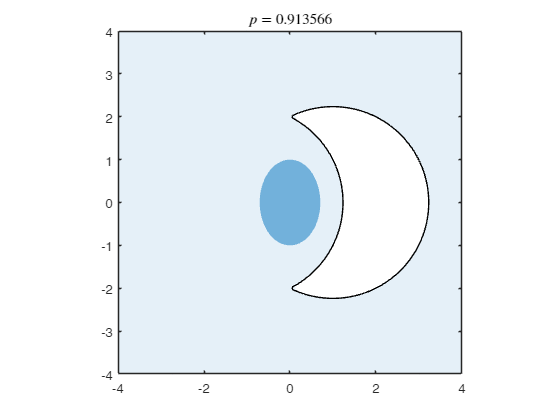

crescent_fun=@(x,y) max(left_circle_fun(x,y), -right_circle_fun(x,y));
integrate_normal(mu,v,crescent_fun,'dom_type','fun','fun_span',5);
axis image; axis([-4 4 -4 4])

Classify normals using this crescent domain:

mu_2=[2.2;0]; v_2=[.5 0; 0 .25];
results=classify_normals([mu,v],[mu_2,v_2],'dom',crescent_fun,'dom_type','fun')

results = struct with fields:
    norm_errmat: [2×2 double]
       norm_err: 0.123484362471861
       norm_d_b: 3.244445524656459
       norm_d_a: 3.111269837220809
       norm_d_e: 3.111269837220809


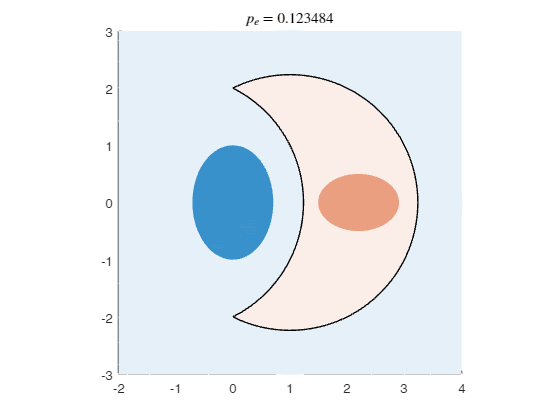

axis image; axis([-2 4 -3 3])

### Ray-trace the domains and use domain operations

Do all of the above by using set operations on faster/more accurate ray-trace domains.

First, define the circles as quadratic domains, then ray-trace them:

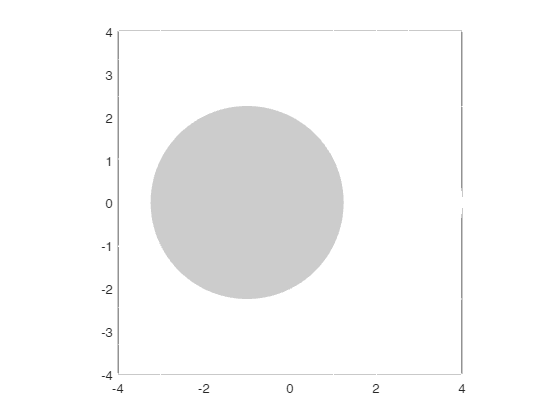

left_circle_quad.q2=-eye(2);
left_circle_quad.q1=[-2;0];
left_circle_quad.q0=4;

plot_boundary(left_circle_quad,2,'fill_colors',[1 1 1; .8*[1 1 1]])
axis image; axis([-4 4 -4 4])

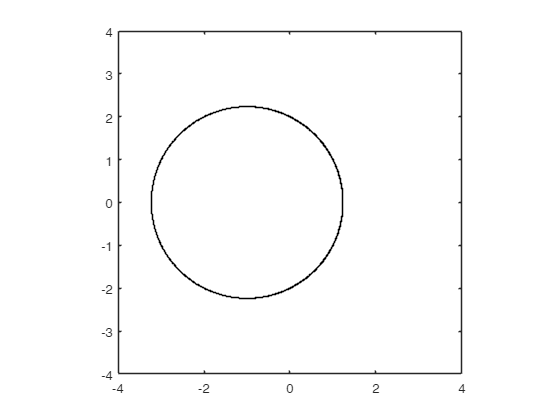

left_circle_ray_trace=@(n,orig) standard_ray_trace(left_circle_quad,n,'mu',orig);
plot_boundary(left_circle_ray_trace,2,'dom_type','ray_trace')
axis image; axis([-4 4 -4 4])


right_circle_quad=left_circle_quad;
right_circle_quad.q1=[2;0];

right_circle_ray_trace=@(n,orig) standard_ray_trace(right_circle_quad,n,'mu',orig);

Now use set operations on the domains:

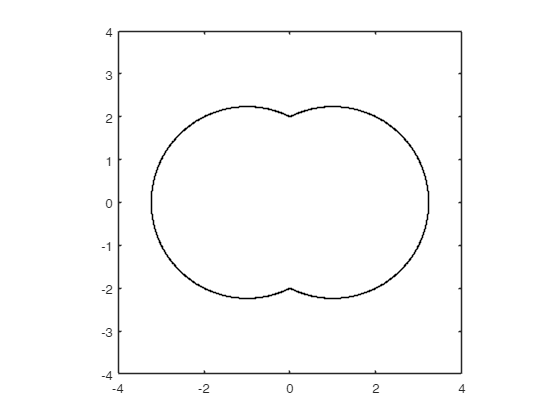

union_ray_trace=@(n,orig) combine_ray_trace_doms({left_circle_ray_trace,right_circle_ray_trace},'or',n,'orig',orig);
plot_boundary(union_ray_trace,2,'dom_type','ray_trace')
axis image; axis([-4 4 -4 4])

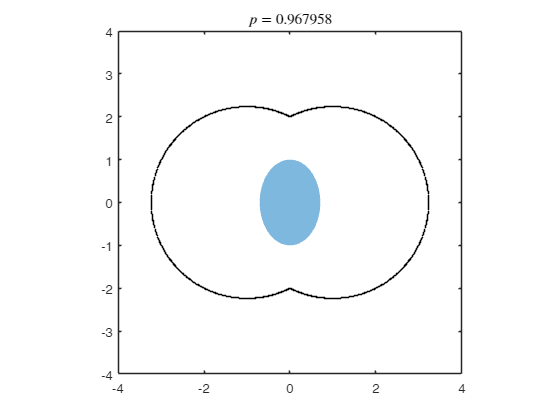

integrate_normal(mu,v,union_ray_trace,'dom_type','ray_trace');
axis image; axis([-4 4 -4 4])

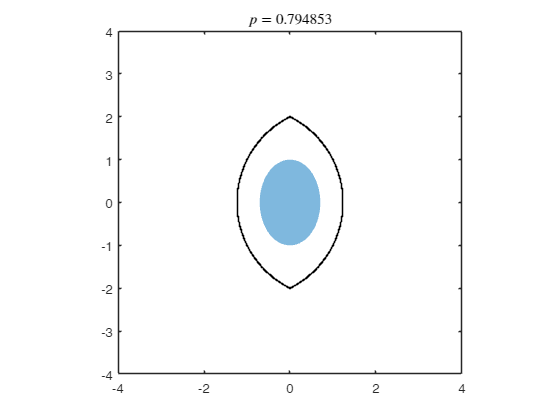

intersection_ray_trace=@(n,orig) combine_ray_trace_doms({left_circle_ray_trace,right_circle_ray_trace},'and',n,'orig',orig);
integrate_normal(mu,v,intersection_ray_trace,'dom_type','ray_trace');
axis image; axis([-4 4 -4 4])

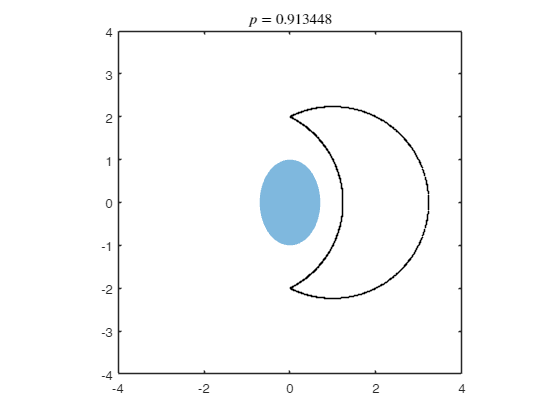

inv_right_circle_ray_trace=@(n,orig) invert_ray_trace_dom(right_circle_ray_trace,n,'orig',orig);
crescent_ray_trace=@(n,orig) combine_ray_trace_doms({left_circle_ray_trace,inv_right_circle_ray_trace},'or',n,'orig',orig);
integrate_normal(mu,v,crescent_ray_trace,'dom_type','ray_trace');
axis image; axis([-4 4 -4 4])

mu_2=[2.2;0]; v_2=[.5 0; 0 .25];
results=classify_normals([mu,v],[mu_2,v_2],'dom',crescent_ray_trace,'dom_type','ray_trace')

results = struct with fields:
    norm_bd_pts: [2×604 double]
    norm_errmat: [2×2 double]
       norm_err: 0.123543800791201
       norm_d_b: 3.244445524656459
       norm_d_a: 3.111269837220809
       norm_d_e: 3.111269837220809


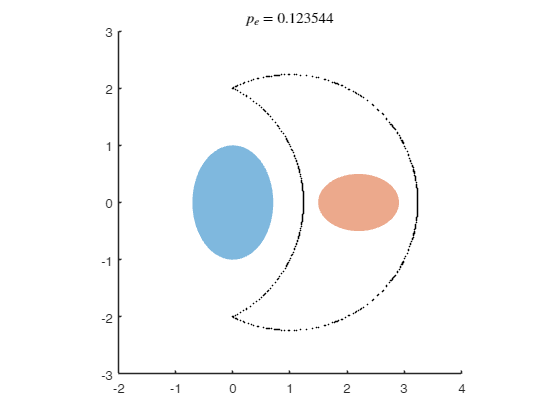

axis image; axis([-2 4 -3 3])

## Classify in 3d

mu_1=[0;0;0]; v_1=eye(3);
mu_2=[2;1;1]; v_2=2*eye(3);

results=classify_normals([mu_1,v_1],[mu_2,v_2],'bd_pts',true)

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_bd_pts: [3×11936 double]
    norm_errmat: [2×2 double]
       norm_err: 0.139027033868878
       norm_d_b: 2.169402167446128
       norm_d_a: 2.000000000000000
       norm_d_e: 2.029223744709153


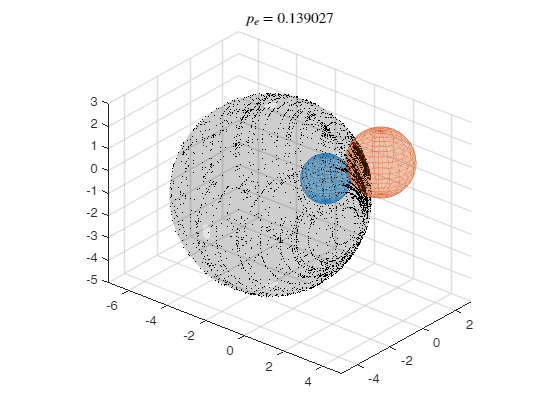

axis([-7 5 -5 3 -5 3])
view([40 28])

## Estimate tiny errors (large $d'$) with high accuracy

format long
dprime_true=200;
mu_1=[0;0;0]; v=eye(3);
mu_2=dprime_true*[1;0;0];

results=classify_normals([mu_1,v],[mu_2,v],'method','ray','force_mc',true,'n_rays',1e7)

Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


results = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: -2.173870622231195e+03
       norm_d_b: 1.999999504004894e+02
       norm_d_a: 200
       norm_d_e: 200


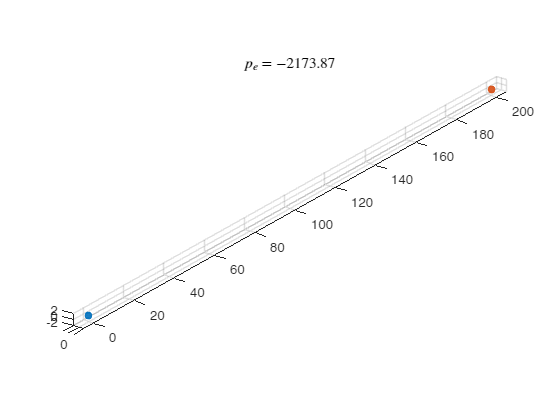

axis image; axis([-5 205 -2 2 -2 2]); view(-53,25)

dprime_computed=results.norm_d_b

dprime_computed =      1.999999504004894e+02


format

## [[paper 1, fig. 8a]](https://arxiv.org/abs/2012.14331) accuracy vs separation between two multinormals

mu_1=[0;0;0];

% both normals have the same covariance, so we can check against
% the true d' (Mahalanobis distance).
v=[1 .5 .7;
  .5  2  1 ;
  .7  1  3];

steps=linspace(1,100,40);
d_true=nan(size(steps));
d_gx2=nan(size(steps));
d_ray=nan(size(steps));

for i=1:length(steps)
    mu_2=steps(i)*[1;1;1];
    
    results_gx2=classify_normals([mu_1,v],[mu_2,v],'method','gx2','AbsTol',0,'RelTol',0,'plotmode',false);
    d_true(i)=results_gx2.norm_d_a;
    d_gx2(i)=results_gx2.norm_d_b;
    
    results_ray=classify_normals([mu_1,v],[mu_2,v],'method','ray','AbsTol',0,'RelTol',0,'plotmode',false);
    d_ray(i)=results_ray.norm_d_b;
end

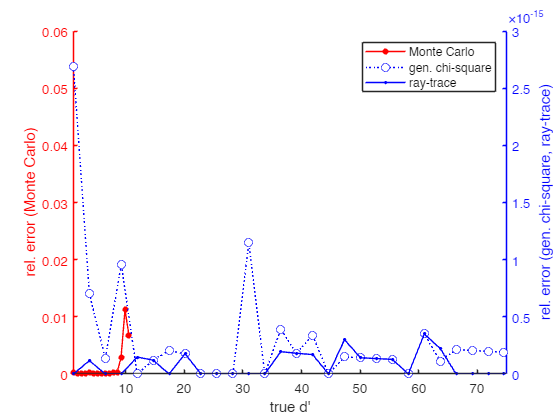

% for Monte Carlo
steps_mc=linspace(1,13,20);
d_true_mc=nan(size(steps_mc));
d_mc=nan(size(steps_mc));

nsamp_mc=1e8;
samp_1=mvnrnd(mu_1,v,nsamp_mc);
samp_0=mvnrnd([0;0;0],v,nsamp_mc);

for i=1:length(steps_mc)
    mu_2=steps_mc(i)*[1;1;1];    
    results_gx2=classify_normals([mu_1,v],[mu_2,v],'method','gx2','plotmode',0);    
    bd=results_gx2.norm_bd;
    d_true_mc(i)=results_gx2.norm_d_a;    

    samp_2=samp_0+mu_2'; 
    d_mc(i)=-2*norminv(samp_value(samp_1,samp_2,bd,'vals',[0 1; 1 0])/(2*nsamp_mc));  
end

% calculate errors in estimates and plot
rel_err_gx2=abs(d_gx2-d_true)./d_true;
rel_err_ray=abs(d_ray-d_true)./d_true;
rel_err_mc=abs(d_mc-d_true_mc)./d_true_mc;

fig=figure; hold on
yyaxis left
plot(d_true_mc,rel_err_mc,'-or','markersize',4,'markerfacecolor','r')
ylim([0 .06]); ylabel('rel. error (Monte Carlo)');
yyaxis right
ax=gca; ax.YAxis(1).Color='r'; ax.YAxis(2).Color='b';
plot(d_true,rel_err_ray,':ob','markersize',6,'markerfacecolor','w')
plot(d_true,rel_err_gx2,'-ob','markersize',2,'markerfacecolor','b')
ylim([0 3e-15])
ylabel('rel. error (gen. chi-square, ray-trace)');
yline(eps) % machine epsilon for double precision
xlim([1 -2*norminv(realmin)]); % upper limit of x axis is largest computable d', corr. to the smallest possible error representable in double-precision 
xlabel 'true d'''
legend({'Monte Carlo','gen. chi-square','ray-trace'})
hold off

## [[paper 2, fig. 8]](https://arxiv.org/abs/2012.14331) accuracy of computing $d'$, order of magnitude of classification error $p_e$, and prob. density $f$ at the classification boundary, as a function of separation between two multinormals

mu_1=[0;0;0];

% both normals have the same covariance, so we can check against
% the true d' (Mahalanobis distance).
v=[1 .5 .7;
    .5  2  1 ;
    .7  1  3];

steps=logspace(-1,6,20);
d_true=nan(size(steps));
d_ray=nan(size(steps));
d_realmin=-2*norminv(realmin);

prob_true=nan(size(steps));
prob_ray=nan(size(steps));

prob_dens_true=cell(size(steps));
prob_dens_ray=nan(size(steps));

% function that is used to compute pdf
prob_dens_bd.q2=zeros(3);
prob_dens_bd.q1=[1;0;0];

syms d
for i=1:length(steps)
    mu_2=steps(i)*[1;1;1];

    results_gx2=classify_normals([mu_1,v],[mu_2,v],'method','gx2','plotmode',false);

    % ground truth values
    d_true(i)=results_gx2.norm_d_e;

    prob_dens_bd_this=prob_dens_bd;
    prob_dens_bd_this.q0=d_true(i)/2;

    if d_true(i)<d_realmin
        tic
        results_ray=classify_normals([mu_1,v],[mu_2,v],'method','ray','AbsTol',0,'RelTol',1e-20,'plotmode',false);
        d_time(i)=toc;
        prob_true(i)=normcdf(d_true(i)/2,'upper');
        tic
        prob_dens_ray(i)=int_norm_ray(mu_1,eye(3),prob_dens_bd_this,'output','prob_dens','AbsTol',0,'RelTol',1e-20);
        prob_dens_time(i)=toc;
    else
        tic
        results_ray=classify_normals([mu_1,v],[mu_2,v],'method','ray','force_mc',true,'n_rays',1e7,'plotmode',false);
        d_time(i)=toc;

        prob_dens_true{i}=subs(normpdf(d/2),d,d_true(i));
        tic
        prob_dens_ray_this=int_norm_ray(mu_1,eye(3),prob_dens_bd_this,'output','prob_dens','force_mc',true,'n_rays',1e7);
        prob_dens_time(i)=toc;
        prob_dens_ray(i)=prob_dens_ray_this;
    end

    d_ray(i)=results_ray.norm_d_b;
    prob_ray(i)=results_ray.norm_err;

end

Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


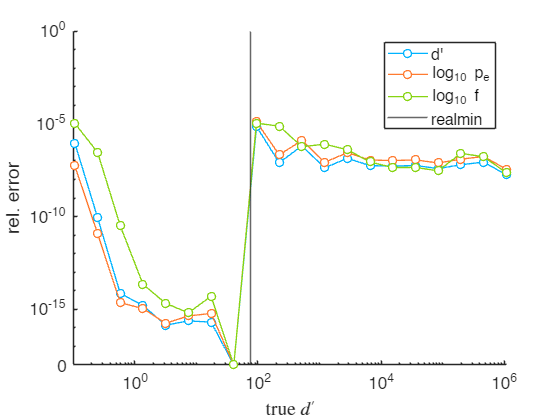


% calculate errors in estimates
rel_err_d=abs(d_ray-d_true)./d_true;
rel_err_d(~rel_err_d)=1e-18; % set 0 to 1e-18

prob_true(d_true<d_realmin)=log10(prob_true(d_true<d_realmin));
x_large=d_true(d_true>d_realmin)/2;
correction=1-1./(x_large.^2)+3./(x_large.^4);
prob_true(d_true>d_realmin)=-x_large.^2/(2*log(10))-log10(x_large)-log10(2*pi)/2+log10(correction);
prob_ray(prob_ray>0)=log10(prob_ray(prob_ray>0));
rel_err_prob=abs((prob_ray-prob_true)./prob_true);

prob_dens_true=-log10(2*pi)/2-(d_true.^2/4)/(2*log(10));
prob_dens_ray(prob_dens_ray>0)=log10(prob_dens_ray(prob_dens_ray>0));
rel_err_prob_dens=abs((prob_dens_ray-prob_dens_true)./prob_dens_true);

% set 0 to 1e-18:
rel_err_prob(~rel_err_prob)=1e-18;
rel_err_prob_dens(~rel_err_prob_dens)=1e-18;

% plot

% define colours
orange=[255 123 49]/255;
sky=[0 179 255]/255;
green=[135 212 18]/255;

figure; hold on

plot(d_true,rel_err_d,'-o','color',sky,'markersize',6,'markerfacecolor','w','LineWidth',1)
plot(d_true,rel_err_prob,'-o','color',orange,'markersize',6,'markerfacecolor','w','LineWidth',1)
plot(d_true,rel_err_prob_dens,'-o','color',green,'markersize',6,'markerfacecolor','w','LineWidth',1)

set(gca,'xscale','log')
set(gca,'yscale','log')
ylabel('rel. error')
xline(d_realmin) % largest computable d', corr. to the smallest possible error representable in double-precision
legend("d'",'log_{10} p_e','log_{10} f','realmin')
xlabel("true $d'$",'interpreter','latex')
axis([1e-1 1.1e6 1e-18 1e0])
set(gca,'ytick',[1e-18 1e-15 1e-10 1e-5 1e0])
set(gca,'yticklabel',{'0','10^{-15}','10^{-10}','10^{-5}','10^0'})
set(gca,'fontsize',13)

## [[paper 1, fig. 4a]](https://arxiv.org/abs/2012.14331) comparing discriminability indices

Comparing the Bayes-optimal discriminability index $d'_b$ against Simpson & Fitter's $d'_a$ and Egan & Clarke's $d'_e$, as discriminability increases.

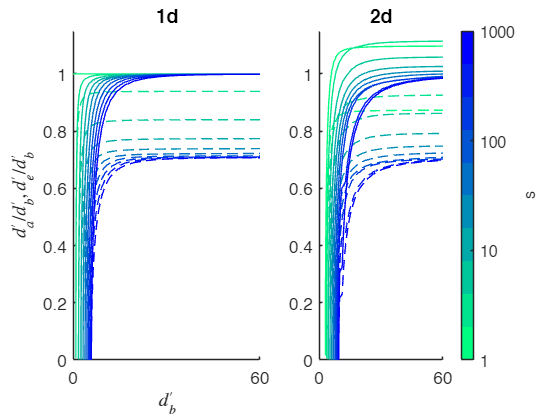

mu_1_2d=[2;4]; v_1_2d=[1 0; 0 3];
mu_2_2d=[5;0]; v_2_2d=[3 0; 0 .01];

sigma=10.^linspace(-6,2,100);
s_list=10.^linspace(0,3,10);

d_b_1d=nan(length(s_list),length(sigma));
d_a_1d=nan(size(d_b_1d));
d_e_1d=nan(size(d_b_1d));

d_b_2d=nan(size(d_b_1d));
d_a_2d=nan(size(d_b_1d));
d_e_2d=nan(size(d_b_1d));

for i=1:length(s_list)
    s=s_list(i);
    d_a_1d(i,:)=1./(sigma*sqrt((s^2+1)/2));
    d_e_1d(i,:)=2./(sigma*(s+1));
    
    parfor j=1:length(sigma)
        results_1d=classify_normals([0,(s*sigma(j))^2],[1,sigma(j)^2],'plotmode',false);
        d_b_1d(i,j)=results_1d.norm_d_b;
        
        v_1_2d_this=(s*sigma(j))^2*v_1_2d;
        v_2_2d_this=sigma(j)^2*v_2_2d;
        results_2d=classify_normals([mu_1_2d,v_1_2d_this],[mu_2_2d,v_2_2d_this],'plotmode',false);
        d_b_2d(i,j)=results_2d.norm_d_b;
        d_a_2d(i,j)=results_2d.norm_d_a;
        d_e_2d(i,j)=results_2d.norm_d_e;
    end
end
figure;
subplot(1,2,1); hold on; axis([0 60 0 1.15])
xlabel("$d'_b$",'interpreter','latex')
ylabel("$d'_a/d'_b, d'_e/d'_b$",'interpreter','latex')
title('1d')
set(gca,'fontsize',13,'xtick',[0 60])
subplot(1,2,2); hold on; axis([0 60 0 1.15])
title('2d')
set(gca,'fontsize',13,'xtick',[0 60])
cmap=colormap(flipud(winter(length(s_list)))); c=colorbar('ticks',linspace(0,1,4),'ticklabels',[1 10 100 1000]);
set(get(c,'label'),'string','s');

for i=1:size(d_b_1d,1)
    subplot(1,2,1)
    plot(d_b_1d(i,:),d_e_1d(i,:)./d_b_1d(i,:),'color',cmap(i,:))
    plot(d_b_1d(i,:),d_a_1d(i,:)./d_b_1d(i,:),'--','color',cmap(i,:))
    
    subplot(1,2,2)
    plot(d_b_2d(i,:),d_e_2d(i,:)./d_b_2d(i,:),'color',cmap(i,:))
    plot(d_b_2d(i,:),d_a_2d(i,:)./d_b_2d(i,:),'--','color',cmap(i,:))
end

## [[paper 1, fig. 3]](https://arxiv.org/abs/2012.14331) Single-interval (yes/no), two-interval, and multi-interval tasks

### Yes/no task

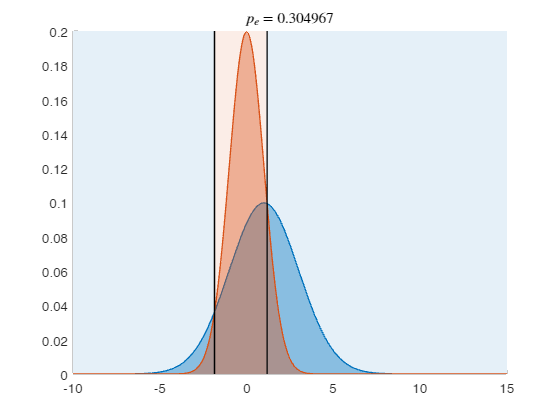

ma=1; va=4;
mb=0; vb=1;

results_yn=classify_normals([ma,va],[mb,vb]);

### Two-interval task

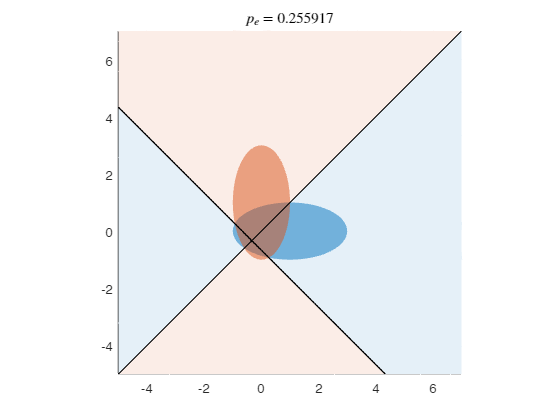

m_ab=[ma; mb];
v_ab=diag([va vb]);

m_ba=[mb; ma];
v_ba=diag([vb va]);

results_2I=classify_normals([m_ab,v_ab],[m_ba,v_ba]);

### Multi-interval task

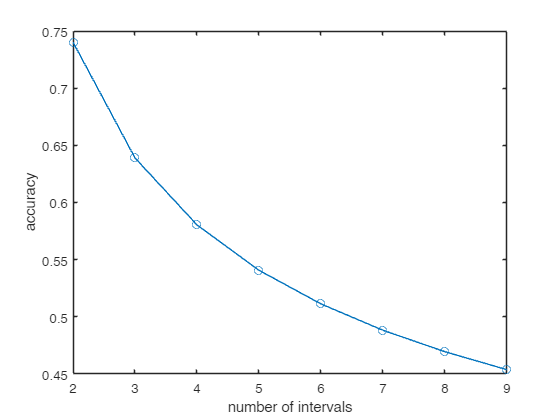

pc=[]; % percent correct
for n=2:9 % # of intervals
    
    % log likelihood ratio of a vs b
    l=results_yn.norm_bd;
    
    % generalized chi-square parameters of l for a and b classes
    [w_a,k_a,lambda_a,s_a,m_a]=norm_quad_to_gx2_params(ma,va,l);    
    [w_b,k_b,lambda_b,s_b,m_b]=norm_quad_to_gx2_params(mb,vb,l);
    
    % when the signal always appears in one of the intervals:
    
    % function that integrates to accuracy
    pc_fun=@(l)gx2pdf(l,w_a,k_a,lambda_a,s_a,m_a).*...
        gx2cdf(l,w_b,k_b,lambda_b,s_b,m_b).^(n-1);
    
    % integrate
    [mu,v]=gx2stat(w_a,k_a,lambda_a,s_a,m_a);
    pc=[pc; [n integral(pc_fun,mu-5*sqrt(v),mu+5*sqrt(v))]];
    
    % when the signal may not appear (with prob. 0.5):
    
    % function that integrates to accuracy
    pc_fun=@(l)gx2pdf(l,w_a,k_a,lambda_a,s_a,m_a).*...
        gx2cdf(l,w_b,k_b,lambda_b,s_b,m_b).^(n-1);
    
    % integrate
    [mu,v]=gx2stat(w_a,k_a,lambda_a,s_a,m_a);
    pc=[pc; [n integral(pc_fun,mu-5*sqrt(v),mu+5*sqrt(v))]];    
end

plot(pc(:,1),pc(:,2),'-o')
xlabel 'number of intervals'
ylabel 'accuracy'

## ROC curves

### [[paper 1, fig. 5]](https://arxiv.org/abs/2012.14331) Generate single-criterion and likelihood-ratio ROC curves from distribution parameters.

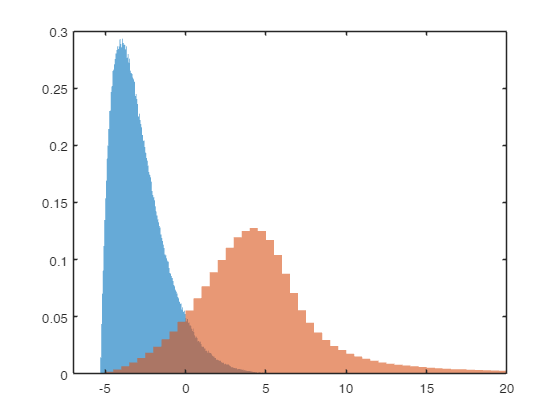

% Two 1d normal distributions
ma_1d=0; va_1d=1;
mb_1d=1; vb_1d=4;

results_1d=classify_normals([ma_1d,va_1d],[mb_1d,vb_1d],'plotmode',0);
fh_1d=results_1d.norm_errmat(:,2)*2; % optimal false alarms and hits
d_a_1d=results_1d.norm_d_a;

% single-criterion and likelihood-ratio boundaries
quad_sc_1d.q2=0;
quad_sc_1d.q1=-1;
quad_lr_1d=results_1d.norm_bd;

% 4d normal and t distribution
ma_4d=[2;0;0;2]; va_4d=eye(4);
vb_4d=diag([1 3 1 5]); dof_b_4d=3;

% draw samples
nsamp_4d=1e6;
xa=mvnrnd(ma_4d,va_4d,nsamp_4d);
xb=mvtrnd(vb_4d,dof_b_4d,nsamp_4d);

% compute log likelihood ratios
la=log(mvtpdf(xa,vb_4d,dof_b_4d))-log(mvnpdf(xa,ma_4d',va_4d));
lb=log(mvtpdf(xb,vb_4d,dof_b_4d))-log(mvnpdf(xb,ma_4d',va_4d));

% remove nan and inf llr's
cleanidx=(~isnan(la)&~isnan(lb)&~isinf(la)&~isinf(lb));
la=la(cleanidx);
lb=lb(cleanidx);
histogram(la,'normalization','pdf','edgecolor','none'); hold on
histogram(lb,'normalization','pdf','edgecolor','none')
xlim([-7 20])

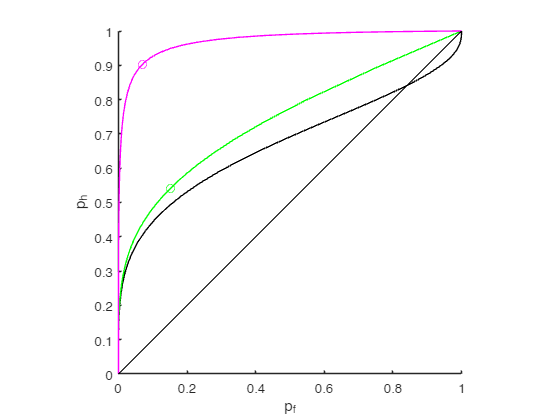


fh_4d=[nnz(la>0)/length(la); nnz(lb>0)/length(lb)];

quad_lr_4d.q2=0;
quad_lr_4d.q1=-1;

% generate ROC curves

% vary single criterion
sc_1d=linspace(-7,10,100);
% vary llr
l_1d=linspace(-1,10,100);
l_4d=[linspace(-6,25,90), linspace(30,700,10)];


ROC_sc_1d=nan(length(sc_1d),2);
ROC_lr_1d=nan(length(l_4d),2);
ROC_lr_4d=nan(length(l_4d),2);

for i=1:length(sc_1d)
    quad_sc_1d.q0=sc_1d(i);
    results=classify_normals([ma_1d,va_1d],[mb_1d,vb_1d],'dom',quad_sc_1d,'plotmode',0);
    ROC_sc_1d(i,:)=results.norm_errmat(:,2)'*2;
    
    quad_lr_1d.q0=l_1d(i);
    results=classify_normals([ma_1d,va_1d],[mb_1d,vb_1d],'dom',quad_lr_1d,'plotmode',0);
    ROC_lr_1d(i,:)=results.norm_errmat(:,2)'*2;
    
    quad_lr_4d.q0=l_4d(i);
    results=classify_normals(la,lb,'input_type','samp','samp_opt',false,'dom',quad_lr_4d,'plotmode',0);
    ROC_lr_4d(i,:)=results.samp_errmat(:,2)'/length(la);    
end

figure; hold on; 
plot(ROC_sc_1d(:,1),ROC_sc_1d(:,2),'-k')
plot(ROC_lr_1d(:,1),ROC_lr_1d(:,2),'-g')
plot(fh_1d(1),fh_1d(2),'og')
plot(ROC_lr_4d(:,1),ROC_lr_4d(:,2),'-m')
plot(fh_4d(1),fh_4d(2),'om')
r=refline(1,0); set(r,'color','k')
xlabel('p_f'); ylabel('p_h');
axis image; axis([0 1 0 1]);
hold off

$d'_a$ equals $\sqrt{2}$ times the $z$-score of the area under single-criterion ROC curve:

results_yn.norm_d_a

ans = 0.6325

AUC_sc=abs(trapz(ROC_sc_1d(:,1),ROC_sc_1d(:,2)));
sqrt(2)*norminv(AUC_sc)

ans = 0.6318

Area under likelihood-ratio ROC curve equals the optimal accuracy in the two-interval task above

AUC_lr_1d=abs(trapz(ROC_lr_1d(:,1),ROC_lr_1d(:,2)))

AUC_lr_1d = 0.7436

1-results_2I.norm_err

ans = 0.7441

AUC_lr_4d=abs(trapz(ROC_lr_4d(:,1),ROC_lr_4d(:,2)))

AUC_lr_4d = 0.9710

p_2I=mean(lb-la>0)

p_2I = 0.9712

### Estimate $d'_b$ from single-criterion ROC curve

First, simulate a noisy ROC curve with the previous 1d normal parameters. Then plot it in z-score (normal deviate) coordinates and fit a line:

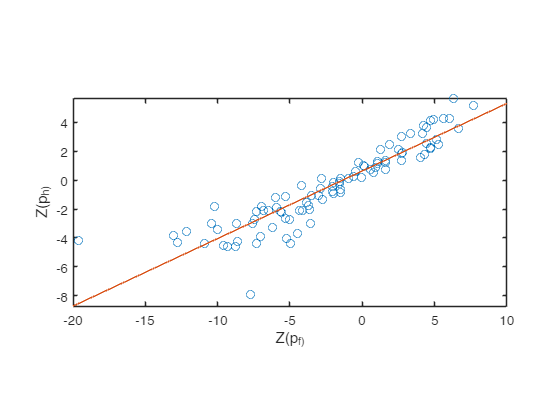

n_samp=10;

ROC=nan(length(sc_1d),2);
for i=1:length(sc_1d)
    samp_a=normrnd(ma_1d,sqrt(va_1d),[n_samp 1]);
    samp_b=normrnd(mb_1d,sqrt(vb_1d),[n_samp 1]);
    quad_sc_1d.q0=sc_1d(i);
    results=classify_normals(samp_a,samp_b,'input_type','samp','dom',quad_sc_1d,'plotmode',0,'samp_opt',false);
    ROC(i,:)=results.norm_errmat(:,2)'*2;    
end

ROC_z=norminv(ROC);
% clean inf's
ROC_z=ROC_z(~isinf(ROC_z(:,1))&~isinf(ROC_z(:,2)),:);

p=polyfit(ROC_z(:,1),ROC_z(:,2),1);
plot(ROC_z(:,1),ROC_z(:,2),'o')
refline(p(1),p(2))
xlabel('Z(p_f)'); ylabel('Z(p_h)');
axis image

Then estimate the parameters of the second normal (the first is standard normal):

m_hat=p(2)/p(1) % true mean was 1

m_hat = 1.3522

s_hat=1/p(1) % true sd was 2

s_hat = 2.1405

Now classify the normals optimally and compute $d'_b$:

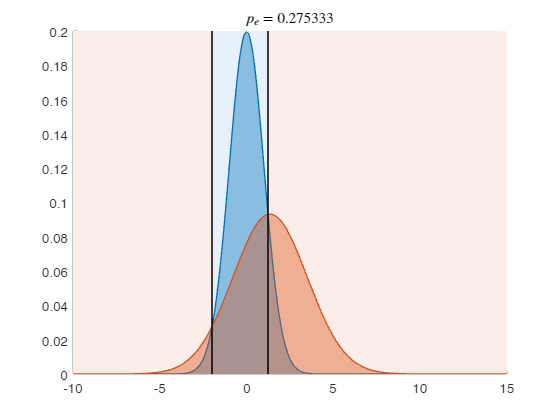

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.2753
       norm_d_b: 1.1935
       norm_d_a: 0.8094
       norm_d_e: 0.8611


results=classify_normals([0,1],[m_hat,s_hat^2])

## [[paper 1, fig. 2a, top]](https://arxiv.org/abs/2012.14331) Integrate normal in a torus defined by function $f(x_1,x_2,x_3)>0$

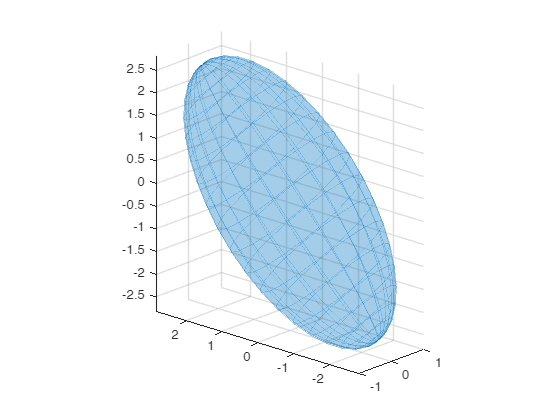

mu=[0;0;0];
v=[1 0 0;
   0 8 4;
   0 4 8];

% plot the error ellipsoid of the normal
figure; plot_normal(mu,v);
axis image
view([-48 20])

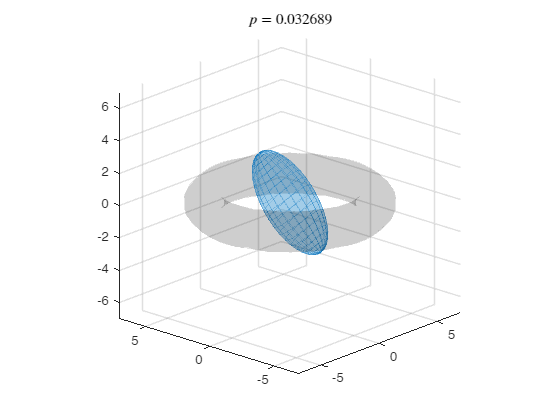

fun_torus=@(x1,x2,x3) 1.5-(5-(x1.^2+x2.^2).^0.5).^2-x3.^2;
figure;
integrate_normal(mu,v,fun_torus,'dom_type','fun','fun_span',3,'fun_resol',10,'RelTol',1e-1);
axis([-7 7 -7 7 -7 7])
view([-48 20])

### pdf and cdf of $f(x)$

Function probability picture:

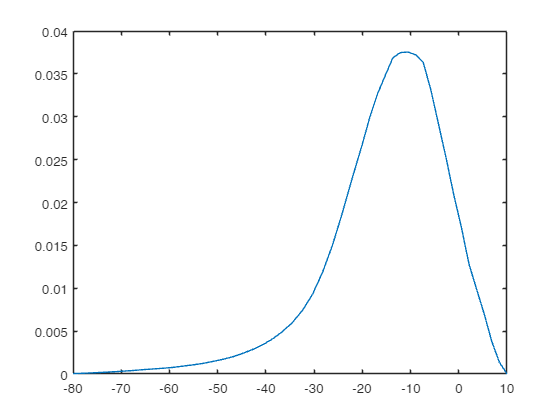

x=[linspace(-80,-20,30) linspace(-20,10,20)];
f=norm_fun_pdf(x,mu,v,fun_torus,'fun_span',3,'fun_resol',10,'RelTol',1e-1,'dx',8);
plot(x,f)

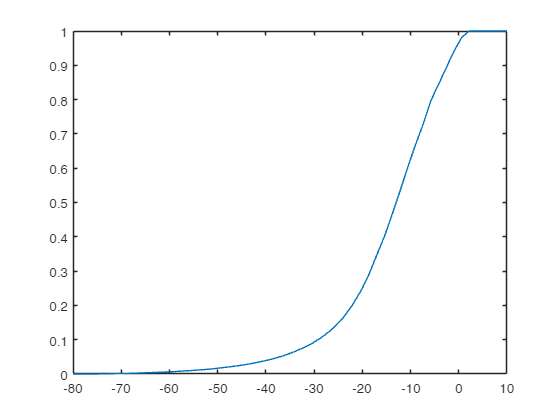

p=norm_fun_cdf(x,mu,v,fun_torus,'fun_span',3,'fun_resol',10,'RelTol',1e-1);
plot(x,p)

## [[paper 1, fig. 2g, top]](https://arxiv.org/abs/2012.14331) Integrate normal in 4d

outside the sphere of radius 5, i.e. $x_1^2+x_2^2+x_3^2+x_4^2>5^2$, i.e. `x'*eye(4)*x + zeros(4,1)'*x -25 >0`

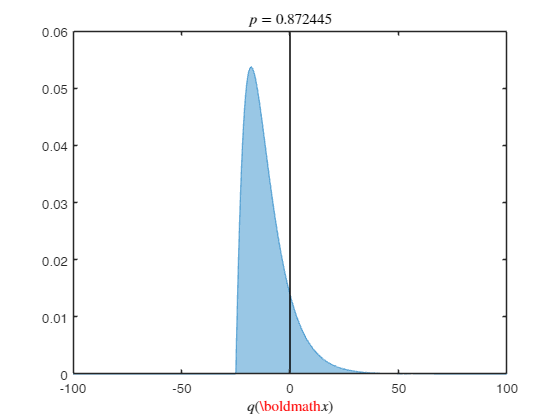

mu=[1;1;1;1]; v=diag([1 2 3 4]);

quad.q2=eye(4);
quad.q1=zeros(4,1);
quad.q0=-25;

figure
p=integrate_normal(mu,v,quad);
xlim([-100 100])

## [[paper 1, fig. 2g, bottom]](https://arxiv.org/abs/2012.14331) Classify in 4d, with priors and outcome values

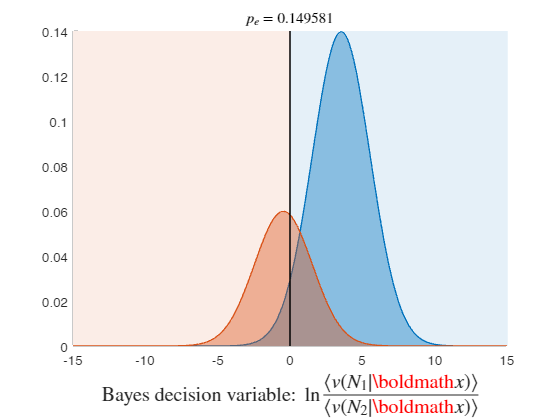

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.1496
       norm_d_b: 2
       norm_d_a: 2
       norm_d_e: 2
    norm_valmat: [2×2 double]
       norm_val: 1.5236


mu_1=[0;0;0;0]; v_1=eye(4);
mu_2=[1;1;1;1]; v_2=eye(4);

% here the Bayes decision variable is normally distributed
results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[2 0; 0 1])

mu_1=[0;0;0;0];
v_1=[1 0 0 0;
     0 2 -1 0;
     0 -1 3 2;
     0 0 2 4];

mu_2=1.5*[1;1;1;1];
v_2=diag([2 2 2 1]);

Correct classification of class 1 is valued 4x than class 2:

% here the Bayes decision variable is distributed as a generalized chi-square
results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[4 0; 0 1])

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.1302
       norm_d_b: 2.3108
       norm_d_a: 2.0852
       norm_d_e: 2.1352
    norm_valmat: [2×2 double]
       norm_val: 2.9431


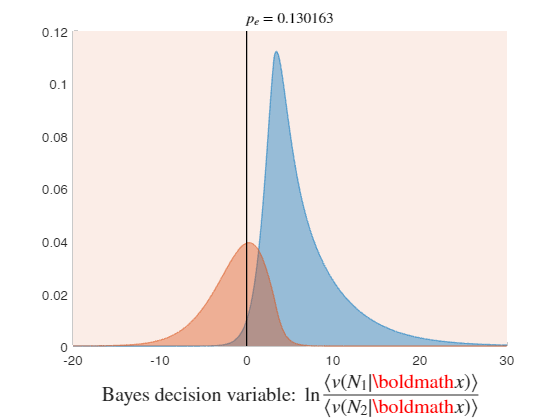

xlim([-20 30])

Use ray method (with Monte Carlo integration):

results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[4 0; 0 1],'method','ray','mc_samples',1e3)

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.1303
       norm_d_b: 2.3108
       norm_d_a: 2.0852
       norm_d_e: 2.1352
    norm_valmat: [2×2 double]
       norm_val: 2.9429


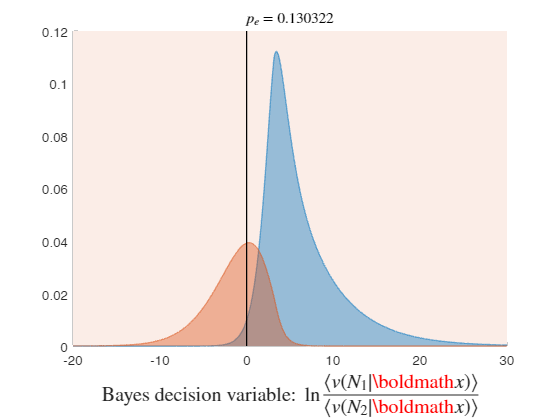

xlim([-20 30])

Now classify using samples:

n_samp=1e3;
results=classify_normals(mvnrnd(mu_1',v_1,n_samp),mvnrnd(mu_2',v_2,n_samp),'input_type','samp','prior_1',.7,'vals',[4 0; 0 1])

results = struct with fields:
               norm_bd: [1×1 struct]
           norm_errmat: [2×2 double]
              norm_err: 0.1263
              norm_d_b: 2.3571
              norm_d_a: 2.1219
              norm_d_e: 2.1777
           norm_valmat: [2×2 double]
              norm_val: 2.9472
               samp_dv: {[1000×1 double]  [1000×1 double]}
          samp_correct: {[1000×1 logical]  [1000×1 logical]}
           samp_errmat: [2×2 double]
              samp_err: 0.2085
           samp_valmat: [2×2 double]
              samp_val: 4541
           samp_opt_bd: [1×1 struct]
           samp_opt_dv: {[1000×1 double]  [1000×1 double]}
    samp_1_opt_correct: [1000×1 logical]
    samp_2_opt_correct: [1000×1 logical]
       samp_opt_errmat: [2×2 double]
          samp_opt_err: 0.1780
       samp_opt_valmat: [2×2 double]
          samp_opt_val: 4575


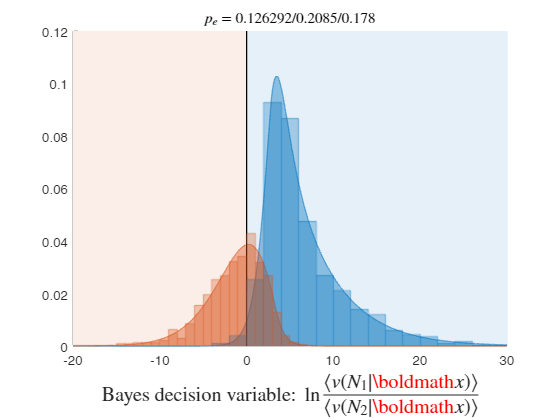

xlim([-20 30])

## [[paper 1, fig. 2b]](https://arxiv.org/abs/2012.14331) Integrate in a 4d polyhedron, using Monte Carlo

mu=zeros(4,1);
v=eye(4);

fun=@(x1,x2,x3,x4) abs(x1)+abs(x2)+abs(x3)+abs(x4);


Find $p(f(x)<1)$, using regular grid integration (quadrature):

p=integrate_normal(mu,v,fun,'lower','dom_type','fun','fun_level',1,'fun_span',3,'fun_resol',10,'plotmode',0)

p = 0.0148

Now use Monte-Carlo integration over rays:

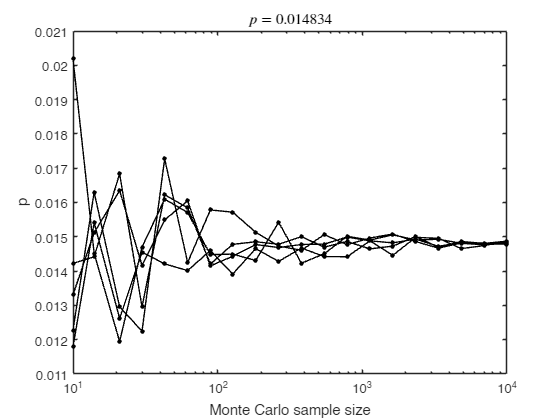

n_rays=round(10.^linspace(1,4,20)); % Monte Carlo sample size of rays
n_repeat=5;
plist=nan(length(n_rays),n_repeat);

for k=1:n_repeat
    for i=1:length(n_rays)
        p=integrate_normal(mu,v,fun,'lower','dom_type','fun','fun_level',1,'fun_span',3,'fun_resol',10,'force_mc',true,'n_rays',n_rays(i),'plotmode',0);
        plist(i,k)=p;
    end
end

plot(n_rays,plist,'-k','marker','.','markersize',10)
xlabel 'Monte Carlo sample size'; ylabel 'p'
set(gca,'xscale','log')
title(sprintf("$p=%f$",mean(plist(end,:))),'interpreter','latex')

Compute cdf and pdf of the polyhedral function:

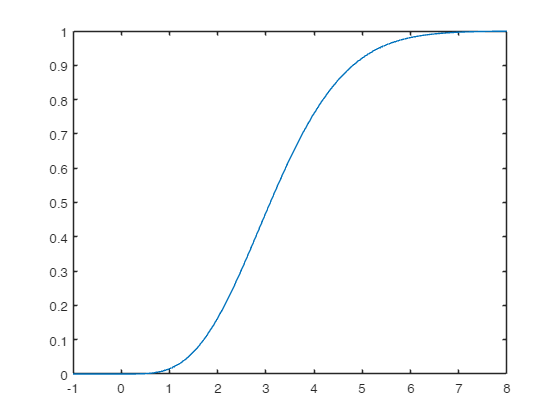

x=linspace(-1,8,50);
p=norm_fun_cdf(x,mu,v,fun);
plot(x,p)

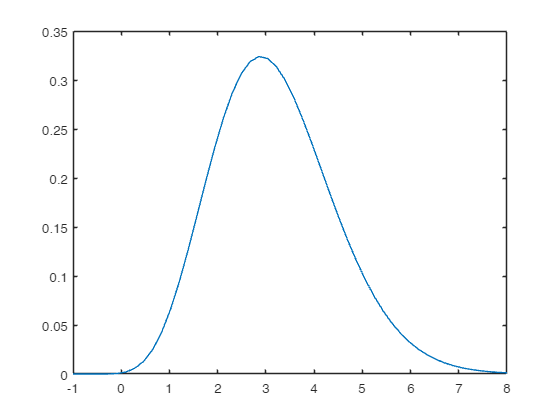

f=norm_fun_pdf(x,mu,v,fun,'dx',0.5);
plot(x,f)

## Classifying 3 1d normals

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3


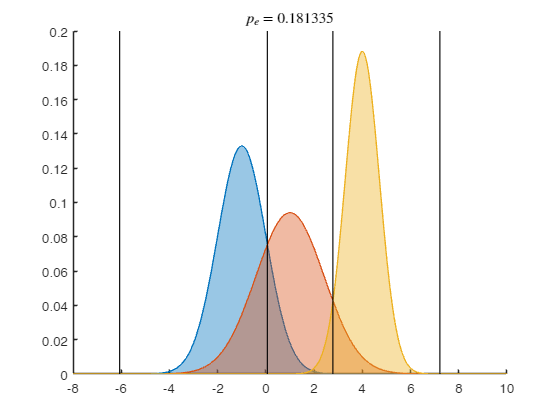

results = struct with fields:
    norm_bd_pts: {3×1 cell}
    norm_errmat: [3×3 double]
       norm_err: 0.1813


normals=struct;
normals(1).mu=-1; normals(1).v=1;
normals(2).mu=1; normals(2).v=2;
normals(3).mu=4; normals(3).v=.5;

results=classify_normals_multi(normals)

% error matrix:
results.norm_errmat

ans =     0.2854    0.0479    0.0000
    0.0847    0.2140    0.0347
    0.0000    0.0141    0.3192


Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3


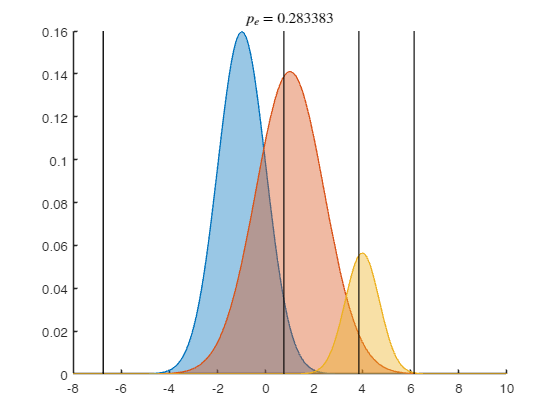

results = struct with fields:
    norm_bd_pts: {3×1 cell}
    norm_errmat: [3×3 double]
       norm_err: 0.2834
    norm_valmat: [3×3 double]
       norm_val: 1.8466


% classify with priors and outcome values
priors=[.4 .5 .1];
vals=[4 0 0; 0 1 -2; 0 0 1];

results=classify_normals_multi(normals,'priors',priors,'vals',vals)

## Classifying 4 2d normals

Define struct of all normals:

normals=struct;
normals(1).mu=[1;0]; normals(1).v=2*eye(2);
normals(2).mu=[0;1]; normals(2).v=eye(2);
normals(3).mu=[-1;0]; normals(3).v=eye(2);
normals(4).mu=[0;-1]; normals(4).v=eye(2);

Plot the multi-class boundary of normal 3:

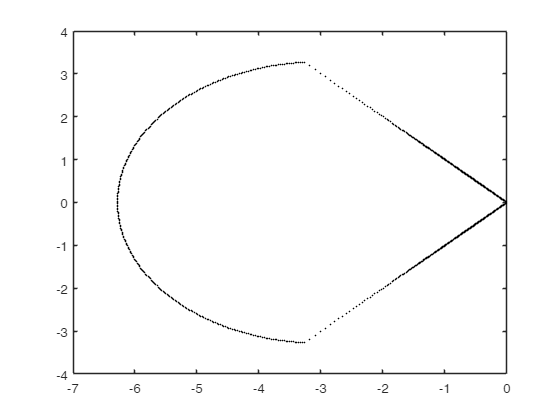

plot_boundary(@(n,orig) opt_class_multi(n,normals,3,'orig',orig),2,'mu',normals(3).mu,'dom_type','ray_trace')

Classify:

results=classify_normals_multi(normals);

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


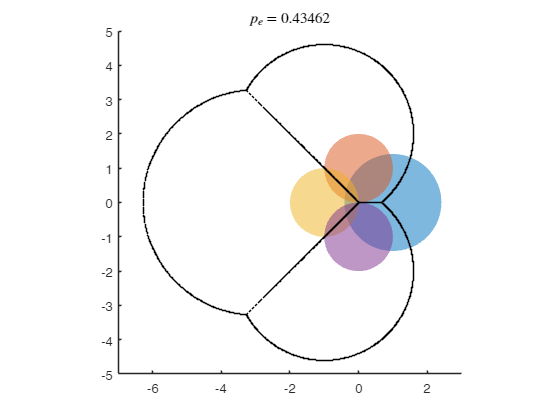

axis([-7 3 -5 5])

Now classify using samples from these normals, with outcome values:

samples=struct;
for i=1:4
    samples(i).sample=mvnrnd(normals(i).mu,normals(i).v,1e4);
end
vals=diag([1 2 3 4]);
results_samp=classify_normals_multi(samples,'input_type','samp','vals',vals)

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


results_samp = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.4587
    norm_valmat: [4×4 double]
       norm_val: 1.5610
     samp_class: {4×1 cell}
    samp_errmat: [4×4 double]
       samp_err: 0.4593
    samp_valmat: [4×4 double]
       samp_val: 62404


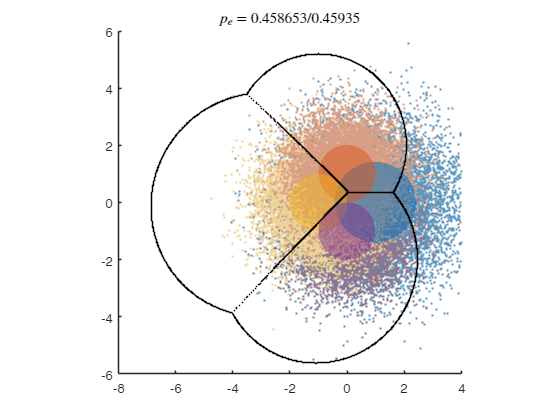

axis([-8 4 -6 6])

Now classify using samples from t distributions similar to these normals:

samples=struct;
for i=1:4
    samples(i).sample=mvtrnd(normals(i).v,3,1e4)+normals(i).mu';
end
results_samp=classify_normals_multi(samples,'input_type','samp')

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2


Integrating normal 1 in domain 3
Integrating normal 1 in domain 4


Integrating normal 2 in domain 1
Integrating normal 2 in domain 2


Integrating normal 2 in domain 3
Integrating normal 2 in domain 4


Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4


Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


results_samp = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.5526
     samp_class: {4×1 cell}
    samp_errmat: [4×4 double]
       samp_err: 0.4524


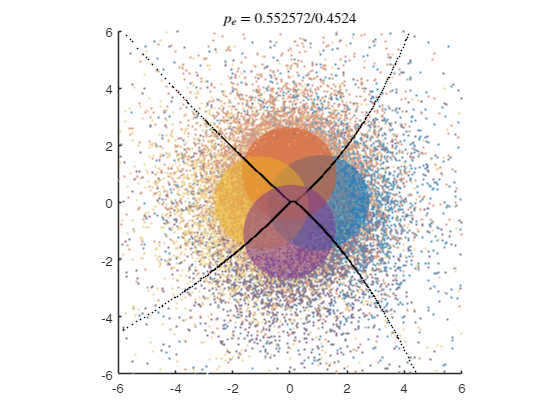

axis([-6 6 -6 6])

## [[paper 1, fig. 2f]](https://arxiv.org/abs/2012.14331) Classifying 7 2d normals

normals=struct;
normals(1).mu=[2;0]; normals(1).v=[2 1; 1 2];
normals(2).mu=[0;1]; normals(2).v=[.5 0; 0 1];
normals(3).mu=[-1;0]; normals(3).v=[1 .3; .3 1];
normals(4).mu=[0;-1]; normals(4).v=[.5 -.5; -.5 1];
normals(5).mu=[-2;2]; normals(5).v=.5*[1 1; 1 5];
normals(6).mu=[2;-3]; normals(6).v=.3*eye(2);
normals(7).mu=[-2;-2.5]; normals(7).v=[1 0; 0 .1];

results=classify_normals_multi(normals)

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 1 in domain 5
Integrating normal 1 in domain 6
Integrating normal 1 in domain 7


Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 2 in domain 5
Integrating normal 2 in domain 6
Integrating normal 2 in domain 7
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 3 in domain 5
Integrating normal 3 in domain 6
Integrating normal 3 in domain 7
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4
Integrating normal 4 in domain 5
Integrating normal 4 in domain 6
Integrating normal 4 in domain 7
Integrating normal 5 in domain 1
Integrating normal 5 in domain 2
Integrating normal 5 in domain 3
Integrating normal 5 in domain 4
Integrating normal 5 in domain 5
Integrating normal 5 in domain 6
Integrating normal 5 in domain 7
Integrating normal 6 in domain 1
Integrating normal 6 in domain 2
Integratin

results = struct with fields:
    norm_bd_pts: {7×1 cell}
    norm_errmat: [7×7 double]
       norm_err: 0.2319


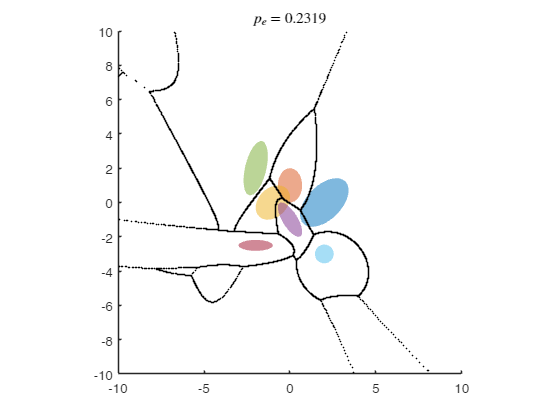

axis([-10 10 -10 10])

## Classifying 4 3d normals

normals=struct;
normals(1).mu=[1;0;0]; normals(1).v=2*eye(3);
normals(2).mu=[0;1;0]; normals(2).v=eye(3);
normals(3).mu=[-1;0;0]; normals(3).v=eye(3);
normals(4).mu=[0;-1;0]; normals(4).v=eye(3);

results=classify_normals_multi(normals)

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


results = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.4254


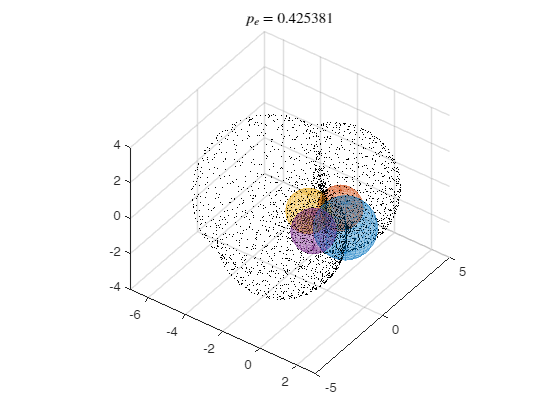

axis([-7 3 -5 5 -4 4]); view([36 39])

## [[paper 1, fig. 2h]](https://arxiv.org/abs/2012.14331) Classifying 4 4d $t$ distribution samples

using Monte-Carlo integration over rays

params=struct;
params(1).mu=[0;-4;-2;-2]; params(1).v=diag([1 2 3 4]);
params(2).mu=[1;1;0;0]; params(2).v=eye(4)/4;
params(3).mu=[3;4;5;7]; params(3).v=eye(4);
params(4).mu=[5;5;7;4]; params(4).v=eye(4);

priors=[.3 .5 .15 .05];

n_samp=1e3;
samples=struct;
for i=1:4
    samples(i).sample=mvtrnd(params(i).v,3,n_samp)+params(i).mu';
end
results_samp=classify_normals_multi(samples,'input_type','samp','priors',priors,'force_mc',true,'n_rays',1e3,'plotmode',[1;1;1;1])

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2


Integrating normal 1 in domain 3


Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2


Integrating normal 2 in domain 3


Integrating normal 2 in domain 4
Integrating normal 3 in domain 1


Integrating normal 3 in domain 2
Integrating normal 3 in domain 3


Integrating normal 3 in domain 4


Integrating normal 4 in domain 1


Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


results_samp = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.0436
     samp_class: {4×1 cell}
    samp_errmat: [4×4 double]
       samp_err: 0.0587


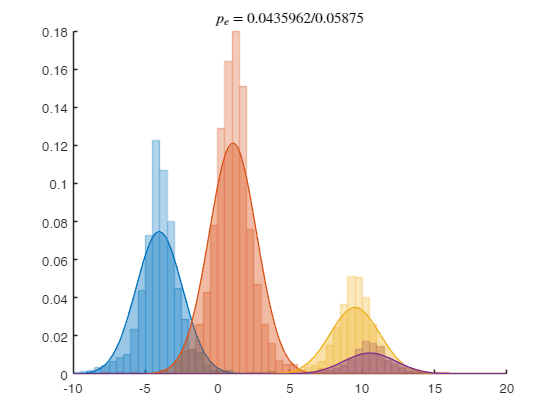

xlim([-10 20])

## [[paper 1, figs. 7a,b](https://arxiv.org/abs/2012.14331)] testing the normal approximation for 2 2d classes

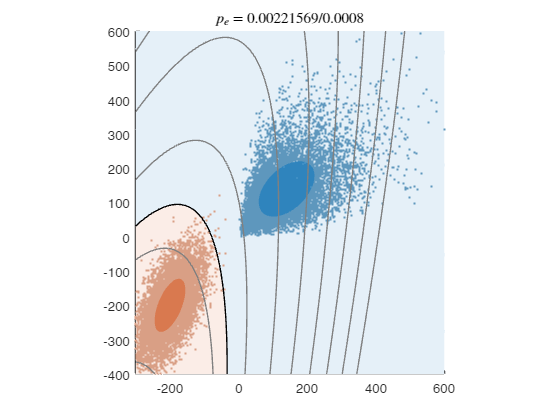

N_samp=1e4; n_samp=1e2;

mu_1=[5 5]; v_1=[1 .5; .5 1]; samp_1=mvnrnd(mu_1,v_1,N_samp).^3; % not normal
mu_2=[-200 -200]; v_2=[1 1; 1 3]*2e3; samp_2=mvnrnd(mu_2,v_2,N_samp);

results=classify_normals(samp_1,samp_2,'input_type','samp','samp_opt',false);
axis([-300 600 -400 600]); hold on
bd=results.norm_bd;

q0_shift=linspace(-50,100,100)';
true_ph=nan(size(q0_shift)); % p(hit)
true_pf=nan(size(q0_shift)); % p(false alarm)
norm_ph=nan(size(q0_shift)); norm_pf=nan(size(q0_shift));

for i=1:length(q0_shift)
    bd_shift=bd; bd_shift.q0=bd.q0-q0_shift(i);
    if ~rem(i,10)
        plot_boundary(bd_shift,2,'plot_type','line','line_color',.5*[1 1 1]);
    end
    results_shift=classify_normals(samp_1,samp_2,'input_type','samp','dom',bd_shift,'samp_opt',false,'plotmode',false);
    
    % true outcomes
    true_ph(i)=results_shift.samp_errmat(1,1)/N_samp;
    true_pf(i)=results_shift.samp_errmat(2,1)/N_samp;
    
    % normal outcomes
    norm_ph(i)=results_shift.norm_errmat(1,1)/.5;
    norm_pf(i)=results_shift.norm_errmat(2,1)/.5;    
end

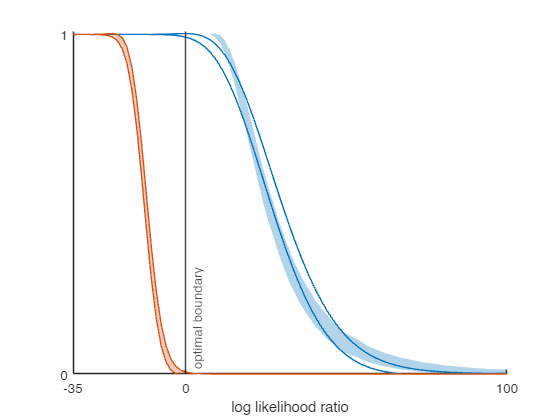


true_ph_sd=sqrt(true_ph.*(1-true_ph)/n_samp);
true_pf_sd=sqrt(true_pf.*(1-true_pf)/n_samp);

norm_ph_sd=sqrt(norm_ph.*(1-norm_ph)/n_samp);
norm_pf_sd=sqrt(norm_pf.*(1-norm_pf)/n_samp);

figure; hold on
colors=colororder;
xline(0,'k','optimal boundary','LabelVerticalAlignment','bottom')

% p(hits)
x=q0_shift;
fill([x;flipud(x)],[true_ph-true_ph_sd;flipud(true_ph+true_ph_sd)],colors(1,:),'facealpha',.3,'linestyle','none');
fill([x;flipud(x)],[norm_ph-norm_ph_sd;flipud(norm_ph+norm_ph_sd)],'k','facecolor','none','edgecolor',colors(1,:));

% p(false alarms)
fill([x;flipud(x)],[true_pf-true_pf_sd;flipud(true_pf+true_pf_sd)],colors(2,:),'facealpha',.3,'linestyle','none');
fill([x;flipud(x)],[norm_pf-norm_pf_sd;flipud(norm_pf+norm_pf_sd)],'k','facecolor','none','edgecolor',colors(2,:));

axis([-35 100 0 1.01]); xlabel('log likelihood ratio')
set(gca,'xtick',[-35 0 100],'ytick',[0 1])

## [[paper 1, figs. 7c,d]](https://arxiv.org/abs/2012.14331) testing the normal approximation for 4 4d $t$ distributions

n_class=4; N_samp=1e4; n_samp=1e2;

% t distribution parameters
params_t=struct;
params_t(1).mu=[0;-4;-2;-2]; params_t(1).v=diag([1 2 3 4]);
params_t(2).mu=[1;1;0;0]; params_t(2).v=eye(4)/4;
params_t(3).mu=[3;4;5;7]; params_t(3).v=eye(4);
params_t(4).mu=[5;5;7;4]; params_t(4).v=eye(4);

samples=struct; params_samp=struct;
for i=1:4
    % generate t samples
    sample=mvtrnd(params_t(i).v,3,N_samp)+params_t(i).mu';
    samples(i).sample=sample;
    % mean and covariance of samples
    params_samp(i).mu=mean(sample)';
    params_samp(i).v=cov(sample)';
end

len_fam=10;
prior_fam=10.^linspace(-6,12,len_fam)';
vscale_fam=10.^linspace(-1,3,len_fam)';

true_p22_mean=nan(len_fam,1);
true_pe_mean=nan(len_fam,1);
true_pe_sd=nan(len_fam,1);

norm_p22_mean=nan(len_fam,1);
norm_pe_mean=nan(len_fam,1);
norm_pe_sd=nan(len_fam,1);

parfor i=1:len_fam
    i
    % generate family of classification domains
    
    % uncomment when varying prior, comment when varying variance
    priors_shift=[1 prior_fam(i) 1 1]; priors_shift=priors_shift/sum(priors_shift);
    domains_shift=cell(n_class,1);
    for k=1:n_class
        domains_shift{k}=@(n,mu) opt_class_multi(n,params_samp,k,'orig',mu,'priors',priors_shift);
    end
    
    % uncomment when varying variance, comment when varying prior
%     params_samp_shift=params_samp;
%     for k=1:n_class
%         params_samp_shift(k).v=vscale_fam(i)*params_samp(k).v;
%     end    
%     domains_shift=cell(n_class,1);
%     for k=1:n_class
%         domains_shift{k}=@(n,mu,v) opt_class_multi(n,params_samp_shift,k,'mu',mu,'v',v);
%     end
    
    results_shift=classify_normals_multi(samples,'input_type','samp','doms',domains_shift,'force_mc',true,'n_rays',5e3,'plotmode',false);
    
    % true error rates
    true_p22_mean(i)=results_shift.samp_errmat(2,2)/N_samp;
    true_pe_mean(i)=results_shift.samp_err;
    samp_errmat_p=results_shift.samp_errmat/(n_class*N_samp);
    errs=sum(~eye(length(samples)).*samp_errmat_p,2);
    accs=diag(samp_errmat_p);
    true_pe_sd(i)=sqrt(sum(errs.*accs)/n_samp);
    
    % normal error rates
    norm_p22_mean(i)=results_shift.norm_errmat(2,2)/sum(results_shift.norm_errmat(2,:));
    norm_pe_mean(i)=results_shift.norm_err;
    errs=sum(~eye(length(samples)).*results_shift.norm_errmat,2);
    accs=diag(results_shift.norm_errmat);
    norm_pe_sd(i)=sqrt(sum(errs.*accs)/n_samp);
    
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.

ans =

     7


ans =

     8


ans =

     2


ans =

     6


ans =

     5


ans =

     4

> In norm_prob_across_rays (line 62)
In <a href="matlab:matlab.internal.language.introspective.errorDocCallback('int_norm_ray', 'C:\Users\ad36226\OneDrive - The University of Texas at Austin\Geisler Lab\gx2\int_norm_ray.m', 94)" style="font-weight:bold">int_norm_ray</a

true_p22_sd=sqrt(true_p22_mean.*(1-true_p22_mean)/n_samp);
norm_p22_sd=sqrt(norm_p22_mean.*(1-norm_p22_mean)/n_samp);

figure; hold on;

% uncomment when varying prior, comment when varying variance
xline(1/3,'k','optimal boundary','LabelVerticalAlignment','bottom')
xlabel('assumed prior ratio p_1/(p_2+p_3+p_4)')
x=prior_fam/3;

% uncomment when varying variance, comment when varying prior
% xline(1,'k','optimal boundary','LabelVerticalAlignment','bottom')
% xlabel('assumed variance scale')
% x=vscale_fam;

% p(2|2)
y=true_p22_mean; dy=true_p22_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],[0.9290 0.6940 0.1250],'facealpha',.3,'linestyle','none');

y=norm_p22_mean; dy=norm_p22_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],'k','facecolor','none','edgecolor',[0.9290 0.6940 0.1250]);


% pe
y=true_pe_mean; dy=true_pe_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],[0.6 0.4 0.2],'facealpha',.3,'linestyle','none');

y=norm_pe_mean; dy=norm_pe_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],'k','facecolor','none','edgecolor',[0.6 0.4 0.2]);

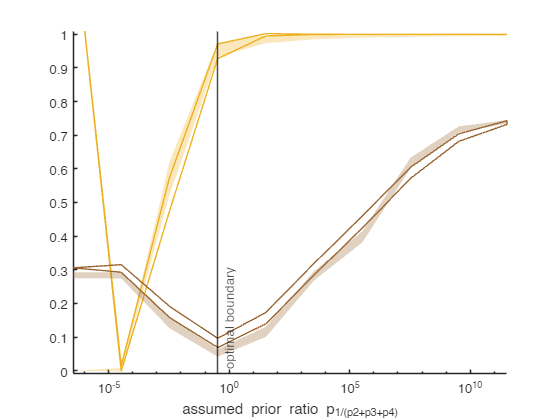


xlim([min(x) max(x)]); set(gca,'xscale','log'); ylim([-.01 1.01])

## [[paper 1, fig. 9b]](https://arxiv.org/abs/2012.14331) Actual vision research data: detecting targets on natural scenes

absent=importdata('target_absent.txt',',',1);
present=importdata('target_present.txt',',',1);

results=classify_normals(present.data,absent.data,'input_type','samp','d_con',true)

results = struct with fields:
               norm_bd: [1×1 struct]
           norm_errmat: [2×2 double]
              norm_err: 8.0400e-05
              norm_d_b: 7.5475
              norm_d_a: 6.8175
              norm_d_e: 7.3973
                 d_con: [3×1 double]
               samp_dv: {[2300×1 double]  [2300×1 double]}
          samp_correct: {[2300×1 logical]  [2300×1 logical]}
           samp_errmat: [2×2 double]
              samp_err: 0.0067
              samp_d_b: 4.9418
           samp_opt_bd: [1×1 struct]
           samp_opt_dv: {[2300×1 double]  [2300×1 double]}
       samp_opt_bd_pts: [3×26070 double]
    samp_1_opt_correct: [2300×1 logical]
    samp_2_opt_correct: [2300×1 logical]
       samp_opt_errmat: [2×2 double]
          samp_opt_err: 0.0026
          samp_opt_d_b: 5.5866


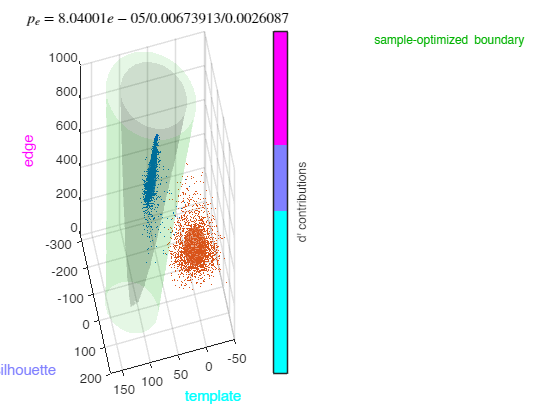

axis normal; axis([-50 170 -320 200 0 1000]); view(166,40)
xlabel('template');
ylabel('silhouette');
zlabel('edge');

## [[paper 1, figs. 9d-h]](https://arxiv.org/abs/2012.14331) Actual vision research data: detecting camouflage

load camouflage_edge_data
samp_absent=[edge_powers_2(:,1),edge_lpr_2(:,1),...
        edge_powers_4(:,1),edge_lpr_4(:,1),...
        edge_powers_8(:,1),edge_lpr_8(:,1)];
    
samp_present=[edge_powers_2(:,2),edge_lpr_2(:,2),...
        edge_powers_4(:,2),edge_lpr_4(:,2),...
        edge_powers_8(:,2),edge_lpr_8(:,2)];

### Classify with 6 features, and measure contributions to d' from each

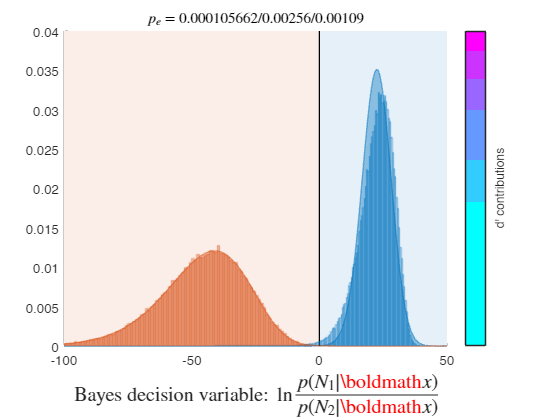

results=classify_normals(samp_present,samp_absent,'input_type','samp','d_con',true);
xlim([-100 50])

### Normality test

bd=results.norm_bd;
N_samp=size(samp_present,1); n_samp=1e2;

q0_shift=linspace(-100,50,100)';
true_ph=nan(size(q0_shift)); % p(hit)
true_pf=nan(size(q0_shift)); % p(false alarm)
norm_ph=nan(size(q0_shift)); norm_pf=nan(size(q0_shift));

for i=1:length(q0_shift)
    bd_shift=bd; bd_shift.q0=bd.q0-q0_shift(i);
    results_shift=classify_normals(samp_present,samp_absent,'input_type','samp','dom',bd_shift,'samp_opt',false,'plotmode',false);
    
    % true outcomes
    true_ph(i)=results_shift.samp_errmat(1,1)/N_samp;
    true_pf(i)=results_shift.samp_errmat(2,1)/N_samp;
    
    % normal outcomes
    norm_ph(i)=results_shift.norm_errmat(1,1)/.5;
    norm_pf(i)=results_shift.norm_errmat(2,1)/.5;    
end

Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.
Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


Using GPU. To use only CPU, set gpu_batch to 0.


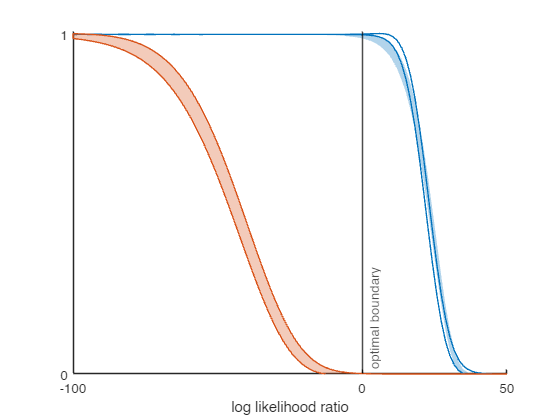


true_ph_sd=sqrt(true_ph.*(1-true_ph)/n_samp);
true_pf_sd=sqrt(true_pf.*(1-true_pf)/n_samp);

norm_ph_sd=sqrt(norm_ph.*(1-norm_ph)/n_samp);
norm_pf_sd=sqrt(norm_pf.*(1-norm_pf)/n_samp);

figure; hold on
colors=colororder;
xline(0,'k','optimal boundary','LabelVerticalAlignment','bottom')

% p(hits)
x=q0_shift;
fill([x;flipud(x)],[true_ph-true_ph_sd;flipud(true_ph+true_ph_sd)],colors(1,:),'facealpha',.3,'linestyle','none');
fill([x;flipud(x)],[norm_ph-norm_ph_sd;flipud(norm_ph+norm_ph_sd)],'k','facecolor','none','edgecolor',colors(1,:));

% p(false alarms)
fill([x;flipud(x)],[true_pf-true_pf_sd;flipud(true_pf+true_pf_sd)],colors(2,:),'facealpha',.3,'linestyle','none');
fill([x;flipud(x)],[norm_pf-norm_pf_sd;flipud(norm_pf+norm_pf_sd)],'k','facecolor','none','edgecolor',colors(2,:));

axis([-100 50 0 1.01]); xlabel('log likelihood ratio')
set(gca,'xtick',[-100 0 50],'ytick',[0 1])

### Classify with 2px cues only

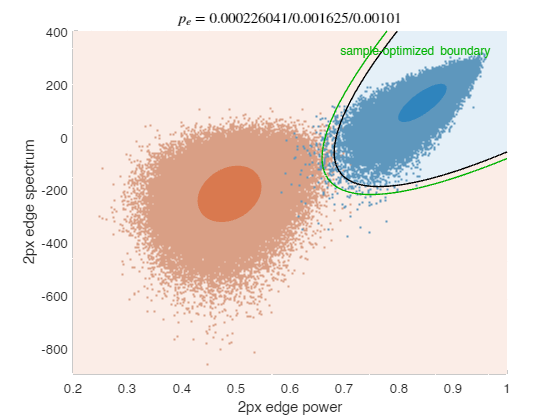

results_2px=classify_normals(samp_present(:,[1 2]),samp_absent(:,[1 2]),'input_type','samp');
axis normal; axis([0.2 1 -900 400])
xlabel '2px edge power'; ylabel '2px edge spectrum'

### Function probability view

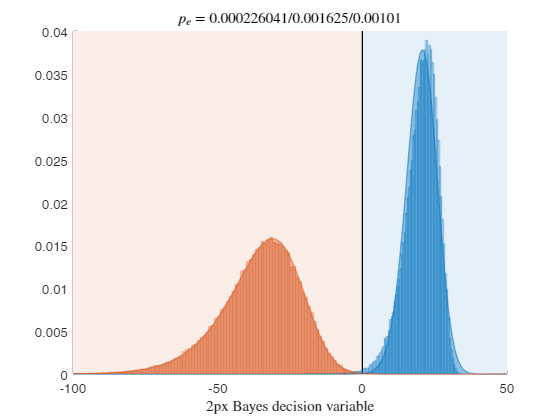

results_2px=classify_normals(samp_present(:,[1 2]),samp_absent(:,[1 2]),'input_type','samp','plotmode','fun_prob');
axis([-100 50 0 .04]); xlabel '2px Bayes decision variable'

### Classify with such combined cues at 3 scales, and measure contribution from each scale

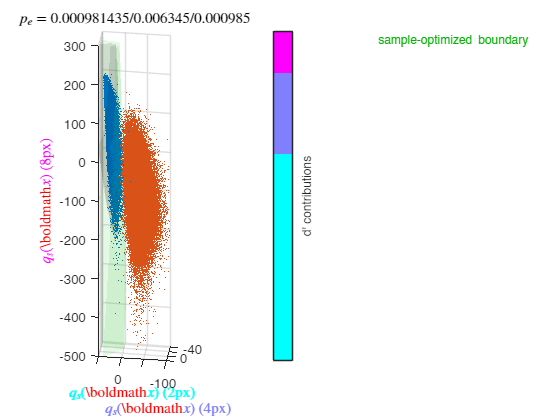

results_4px=classify_normals(samp_present(:,[3 4]),samp_absent(:,[3 4]),'input_type','samp','plotmode',0);
results_8px=classify_normals(samp_present(:,[5 6]),samp_absent(:,[5 6]),'input_type','samp','plotmode',0);
results_joint=classify_normals([results_2px.samp_opt_dv{1},results_4px.samp_opt_dv{1},results_8px.samp_opt_dv{1}],...
    [results_2px.samp_opt_dv{2},results_4px.samp_opt_dv{2},results_8px.samp_opt_dv{2}],'input_type','samp','d_con',true);
axis([-100 50 -45 20 -500 300]); view(-172,31)
xlabel('$q_s(${\boldmath$x$}$)$ (2px)','interpreter','latex');
ylabel('$q_s(${\boldmath$x$}$)$ (4px)','interpreter','latex');
zlabel('$q_s(${\boldmath$x$}$)$ (8px)','interpreter','latex');